# Assignment 04 - Use of Matlab to investigate compartmental systems

### 200488E - PUSHPAKUMARA H.M.R.M.

_

## Part 01

### 1.

#### Response for step input *A(t) = 1 g/kg/h* for t > 0

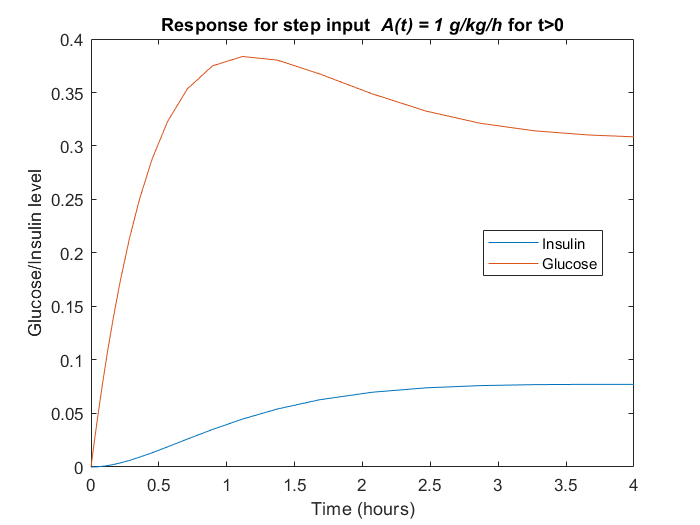

[t,y] = ode23('Unit_Step', [0,4], [0,0]);
plot(t,y);
legend('Insulin','Glucose',"Location","best");
xlabel ('Time (hours)');
ylabel ('Glucose/Insulin level');
title ('Response for step input {\it A(t) = 1 g/kg/h} for t>0')

#### Response for bolus input

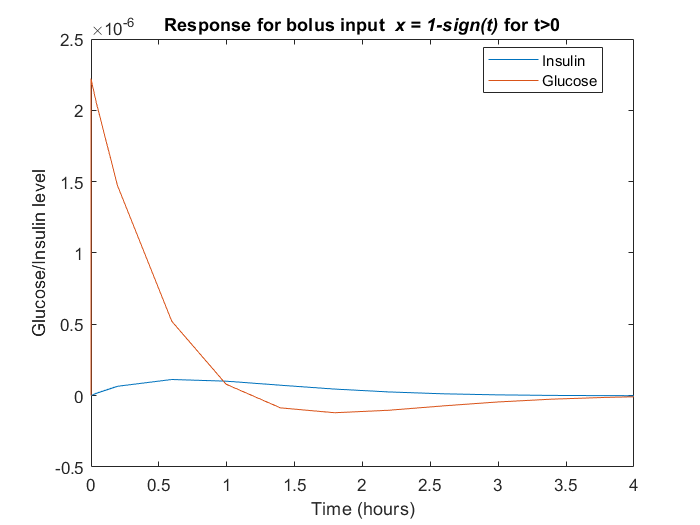

[t,y] = ode23('bolus', [0,4], [0,0]);
plot(t,y);
legend('Insulin','Glucose',"Location","best");
xlabel ('Time (hours)');
ylabel ('Glucose/Insulin level');
title ('Response for bolus input {\it x = 1-sign(t)} for t>0')

### Simulating a diabetic subject without insulin input

In a diabetic patient, the pancreatic beta cells are not as responsive to glucose as they are in a healthy person. This means that even when blood glucose levels are high, the beta cells may not release enough insulin to lower blood sugar levels. As a result, glucose is not able to be converted into glycogen as efficiently, and it builds up in the bloodstream.

In this model the coefficient of ***g*** in the $$$ \frac{\mathrm{di}}{\mathrm{d}t}$ equation represents the strength of the relationship between insulin release and glucose levels. In a diabetic patient, this relationship is weaker than in a healthy person, so the coefficient of ***g*** is reduced. In the equation, the coefficient has been made to ***0.01***, which means that insulin release is very weakly correlated with glucose levels.

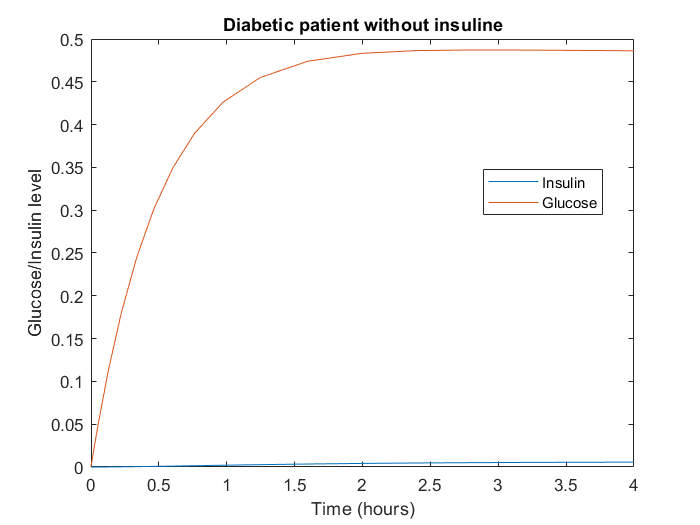

[t,y] = ode23('diabetic', [0,4], [0,0]);
plot(t,y);
legend('Insulin','Glucose',"Location","best");
xlabel ('Time (hours)');
ylabel ('Glucose/Insulin level');
title ('Diabetic patient without insuline')

We can see here the glucose level has not been reduced.

### Simulating a diabetic subject with insulin input

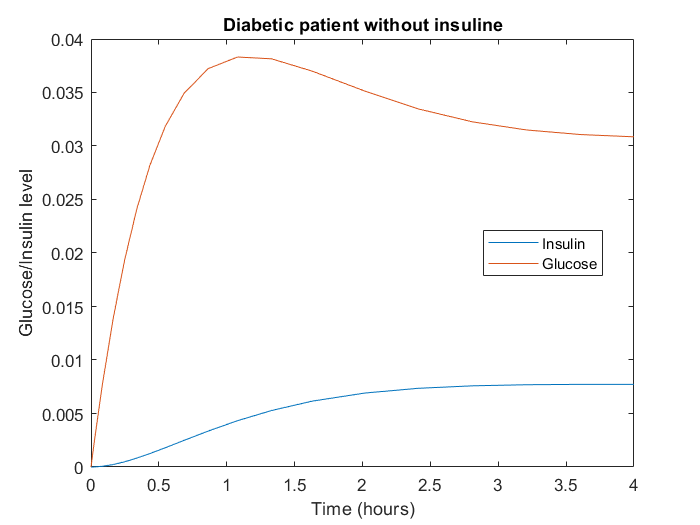

[t,y] = ode23('insulin_infusion', [0,4], [0,0]);
plot(t,y);
legend('Insulin','Glucose',"Location","best");
xlabel ('Time (hours)');
ylabel ('Glucose/Insulin level');
title ('Diabetic patient without insuline')

Since there is insulin input of ***0.1g/kg/h ***we can see the reduction of the glucose level.

_

### 2.

Here I have change the ***riggs*** function name to another names for my convenient.

### Iodine intake 150 μg/day for 10 days

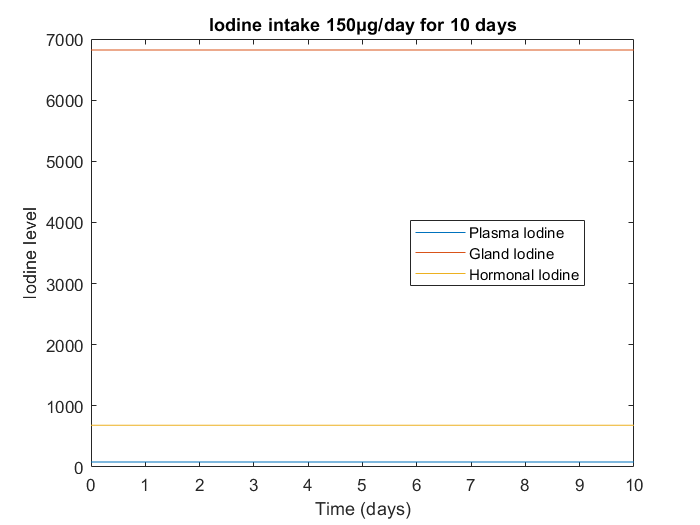

[t,y] = ode23('iodine_150',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Iodine intake 150μg/day for 10 days')

### Iodine intake 15 μg/day for 10 days

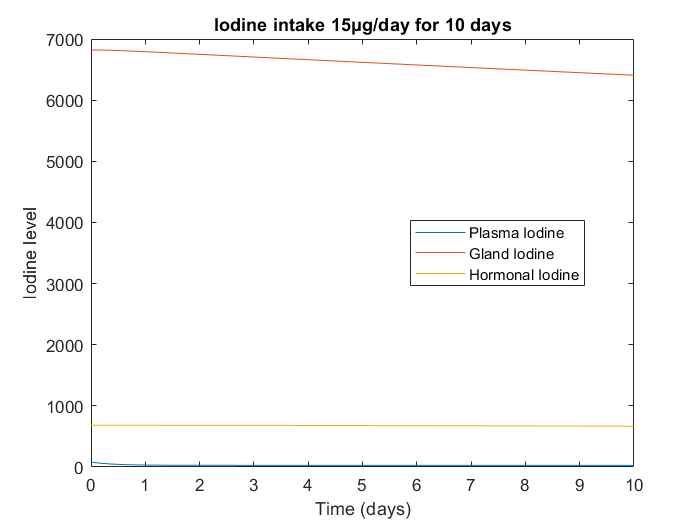

[t,y] = ode23('iodine_15',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Iodine intake 15μg/day for 10 days')

### Iodine intake 150 μg/day for 300 days

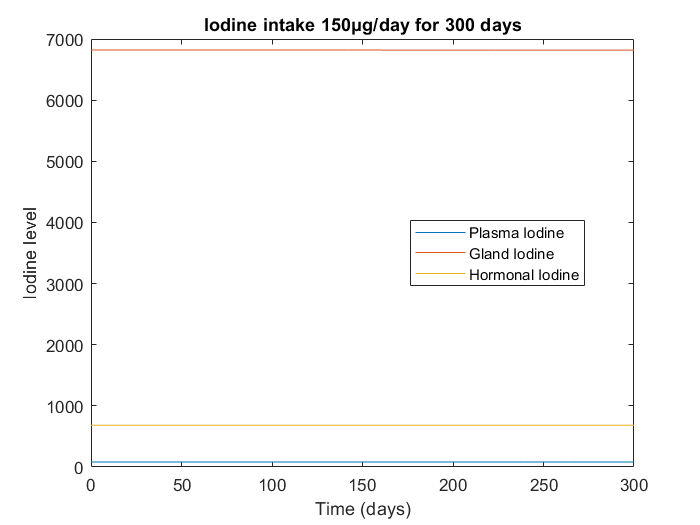

[t,y] = ode23('iodine_150',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Iodine intake 150μg/day for 300 days')

### Iodine intake 15 μg/day for 300 days

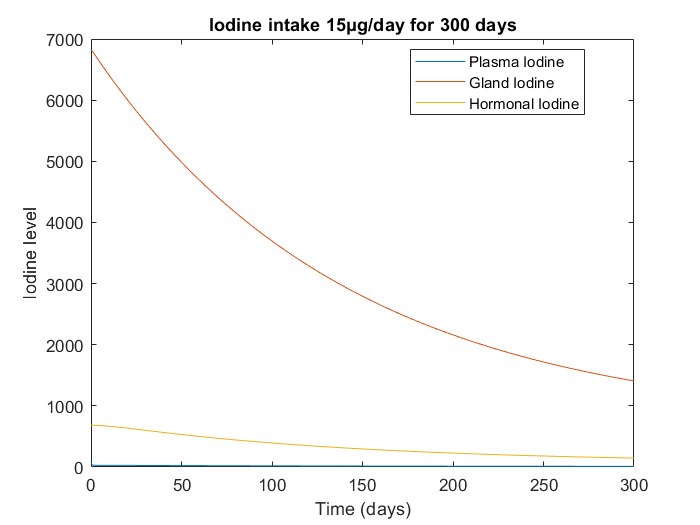

[t,y] = ode23('iodine_15',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Iodine intake 15μg/day for 300 days')

_

_

### a. Hypothyroidism due to autoimmune thyroid disease

In this disease, the thyroid hormone-producing cells die. This results in a decline in thyroid hormone production, even though iodine intake remains normal. This can be modeled using the Riggs model by reducing the k2 parameter. In the simulation, the k2 value was reduced from 0.01 to 0.005.

The k2 parameter represents the rate of degradation of thyroid hormone. By reducing the k2 value, we are effectively slowing down the degradation of thyroid hormone. This means that there will be more thyroid hormone available in the body, even though the cells that produce it are dying.

_

#### For 10 days

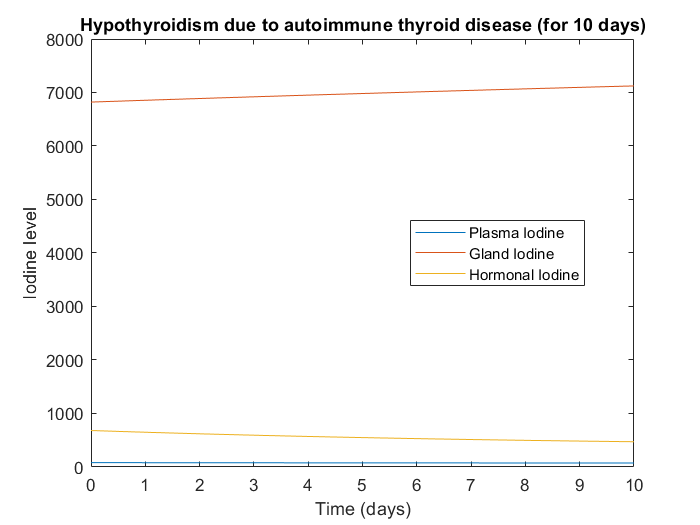


[t,y] = ode23('iodine_a',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Hypothyroidism due to autoimmune thyroid disease (for 10 days)')

#### For 300 days

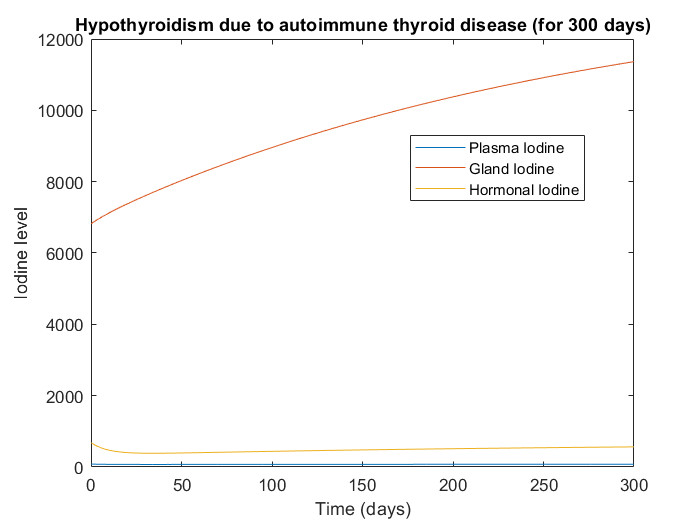

[t,y] = ode23('iodine_a',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Hypothyroidism due to autoimmune thyroid disease (for 300 days)')

The amount of iodine in the thyroid gland has increased over time, but the amount of thyroid hormone and plasma iodine has decreased. This is because the autoimmune disease has damaged the thyroid gland and impaired its ability to produce and release thyroid hormone.

_

_

### b. Hypothyroidism due to low Iodine intake

This disease, which is caused by a lack of iodine in the diet, can be modeled using the Riggs model by reducing the input B1(t). In the simulation, the value of B1(t) was reduced from 150 to 50, which represents a significant decrease in iodine intake.

_

#### For 10 days

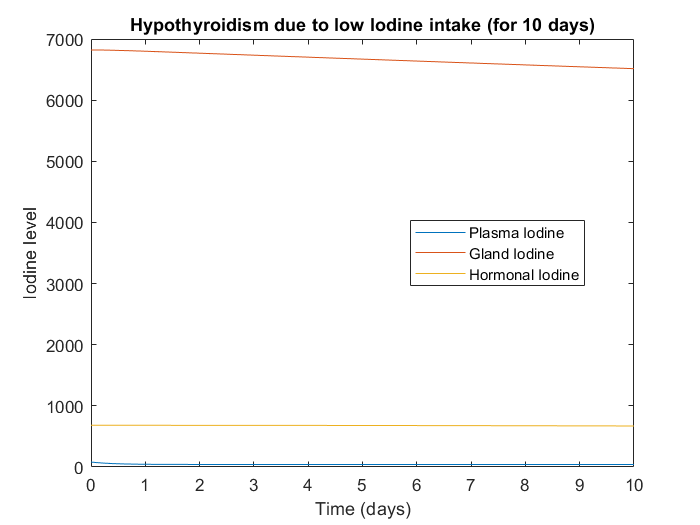

[t,y] = ode23('iodine_b',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Hypothyroidism due to low Iodine intake (for 10 days)')

#### For 300 days

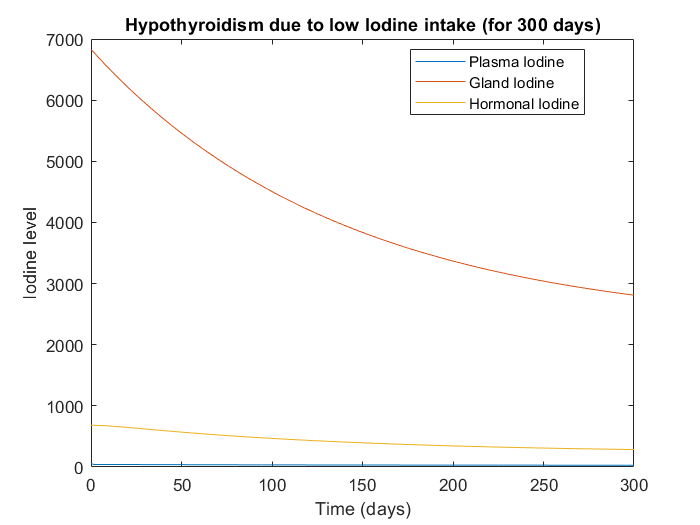

[t,y] = ode23('iodine_b',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Hypothyroidism due to low Iodine intake (for 300 days)')

The level of iodine in the thyroid gland has decreased over time, and this has led to a decrease in the production of thyroid hormone.

_

_

### c. Hyperthyroidism due to Grave’s disease

Graves' disease is a condition in which the thyroid gland produces too much thyroid hormone. This can lead to a number of symptoms, including weight loss, rapid heart rate, and irregular heartbeat. The Riggs model can be used to simulate the effects of Graves' disease. In the simulation, the k2 parameter was increased from 0.01 to 0.08. This represents an increase in the rate of degradation of thyroid hormone. This means that there will be less thyroid hormone available in the body, which can help to alleviate the symptoms of Graves' disease.

_

#### For 10 days

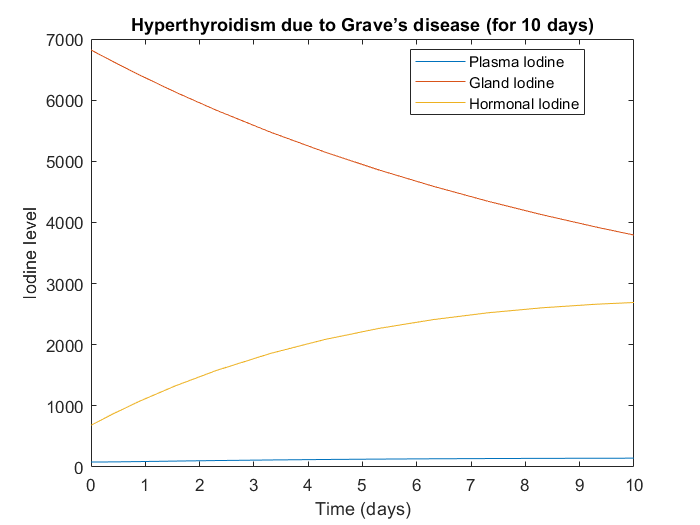

[t,y] = ode23('iodine_c',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Hyperthyroidism due to Grave’s disease (for 10 days)')

#### For 300 days

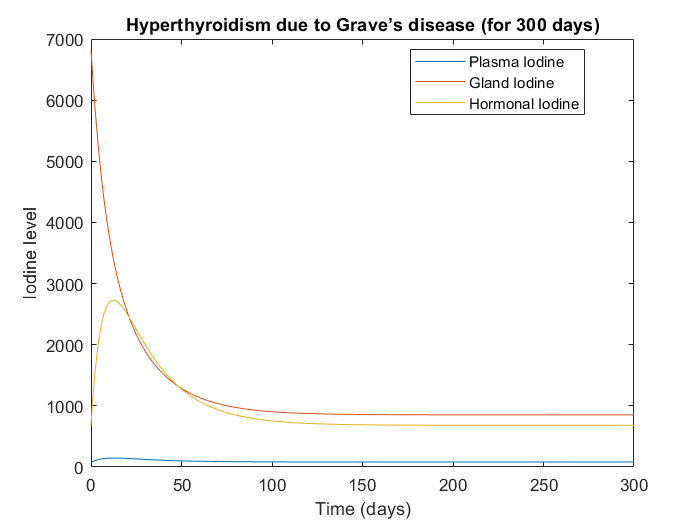

[t,y] = ode23('iodine_c',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Hyperthyroidism due to Grave’s disease (for 300 days)')

_

_

### d. 

### Goitre

Goiter is a swelling of the thyroid gland that can be caused by a lack of iodine in the diet. Iodine is essential for the production of thyroid hormone, and when there is not enough iodine in the body, the thyroid gland enlarges in an attempt to capture more iodine. This can cause a lump to form in the front of the neck, which can move up and down when the patient swallows.

The Riggs model is a mathematical model that can be used to simulate the effects of iodine deficiency on the thyroid gland. In the model, the input B1(t) represents the amount of iodine in the diet. When the value of B1(t) is reduced, it simulates a decrease in iodine intake. In the simulation, the value of B1(t) was reduced from 150 to 30, which represents a significant decrease in iodine intake.

This reduction in iodine intake causes the thyroid gland to enlarge in an attempt to capture more iodine. This can lead to the formation of a goiter.

_

#### For 10 days

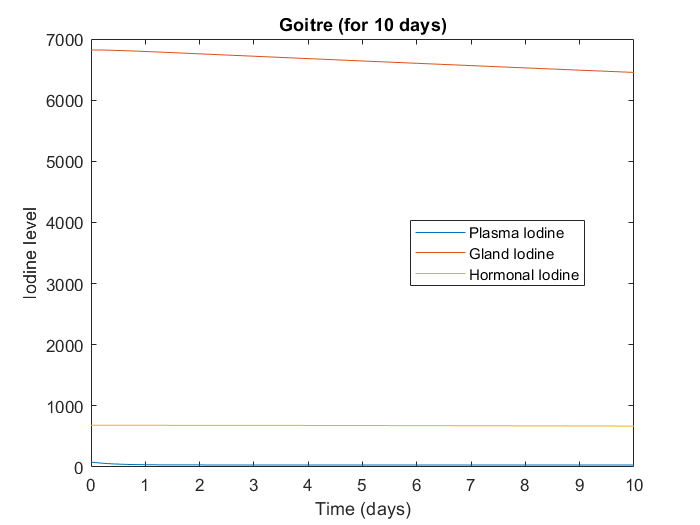

[t,y] = ode23('iodine_d',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Goitre (for 10 days)')

#### For 300 days

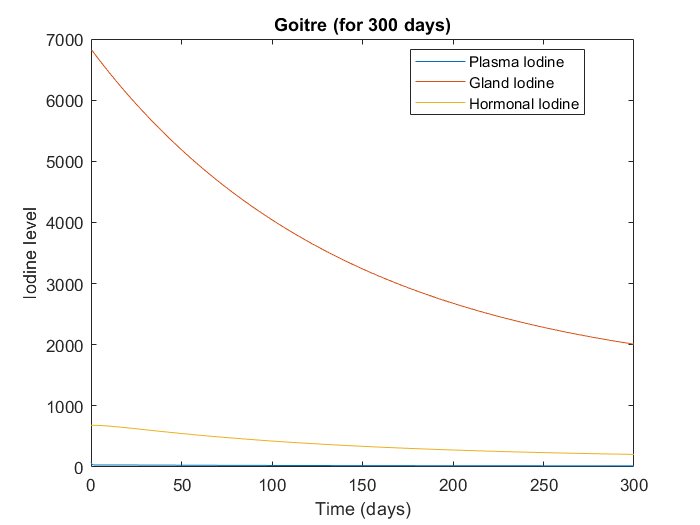

[t,y] = ode23('iodine_d',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Goitre (for 300 days)')

_

### Tumors

Thyroid tumors are often asymptomatic in the early stages, but as they grow, they can cause a lump to appear in the neck. Other symptoms may include changes in voice and difficulty swallowing. Some thyroid tumors, also known as thyroid nodules, can produce too much thyroid hormone, leading to hyperthyroidism. This can be modeled using the Riggs model by increasing the k2 parameter. In the simulation, the k2 value was increased from 0.01 to 0.2.

_

#### For 10 days

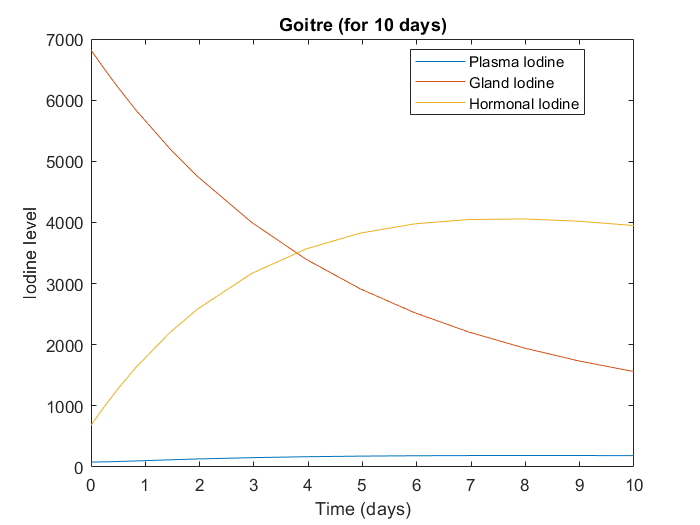

[t,y] = ode23('iodine_d_1',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Tumors (for 10 days)')

#### For 300 days

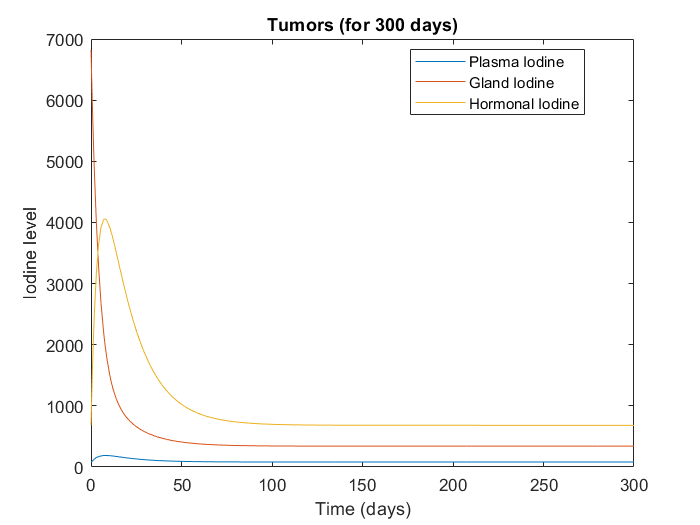

[t,y] = ode23('iodine_d_1',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine',"Location","best")
xlabel ('Time (days)');
ylabel ('Iodine level');
title ('Tumors (for 300 days)')

_

_

_

## Part 02

_

### **1. Simulink Insulin and Glucose model**

    $$$ \frac{\mathrm{d}i}{\mathrm{d}t}$ = −0.8𝑖+0.2𝑔+𝐵(𝑡) 

    $$$ \frac{\mathrm{d}g
}{\mathrm{d}t}$  = −5𝑖 −2𝑔 + 𝐴(𝑡)

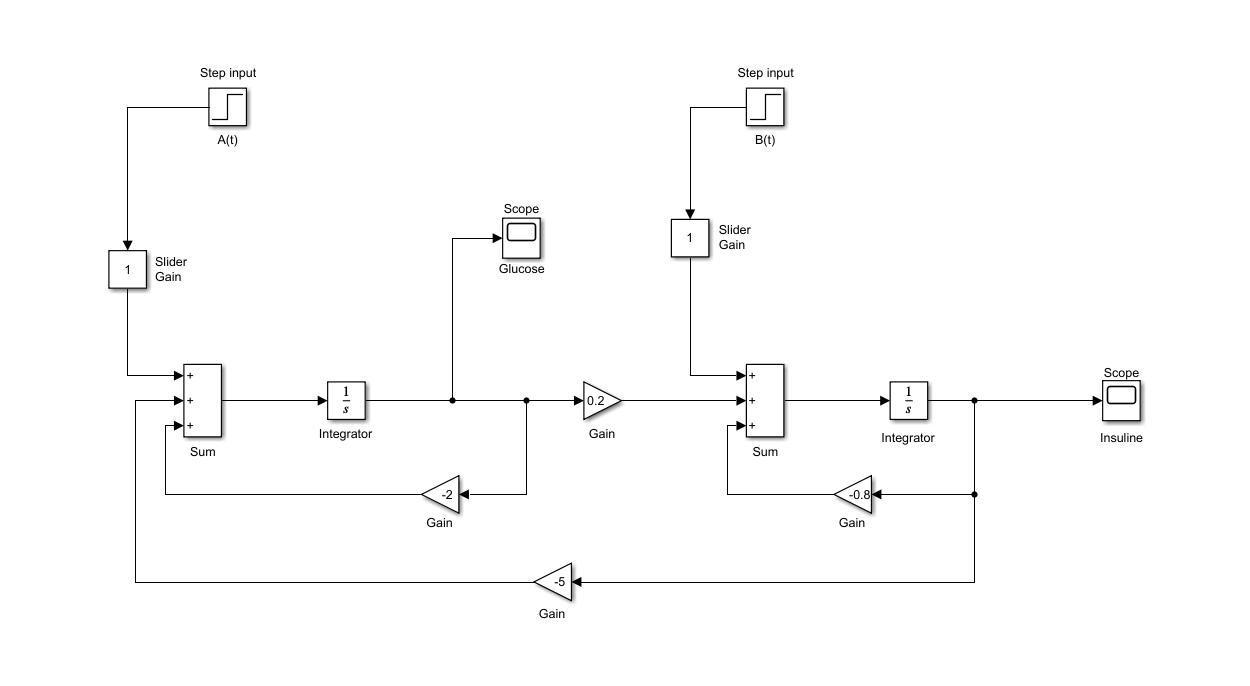

**Glucose**

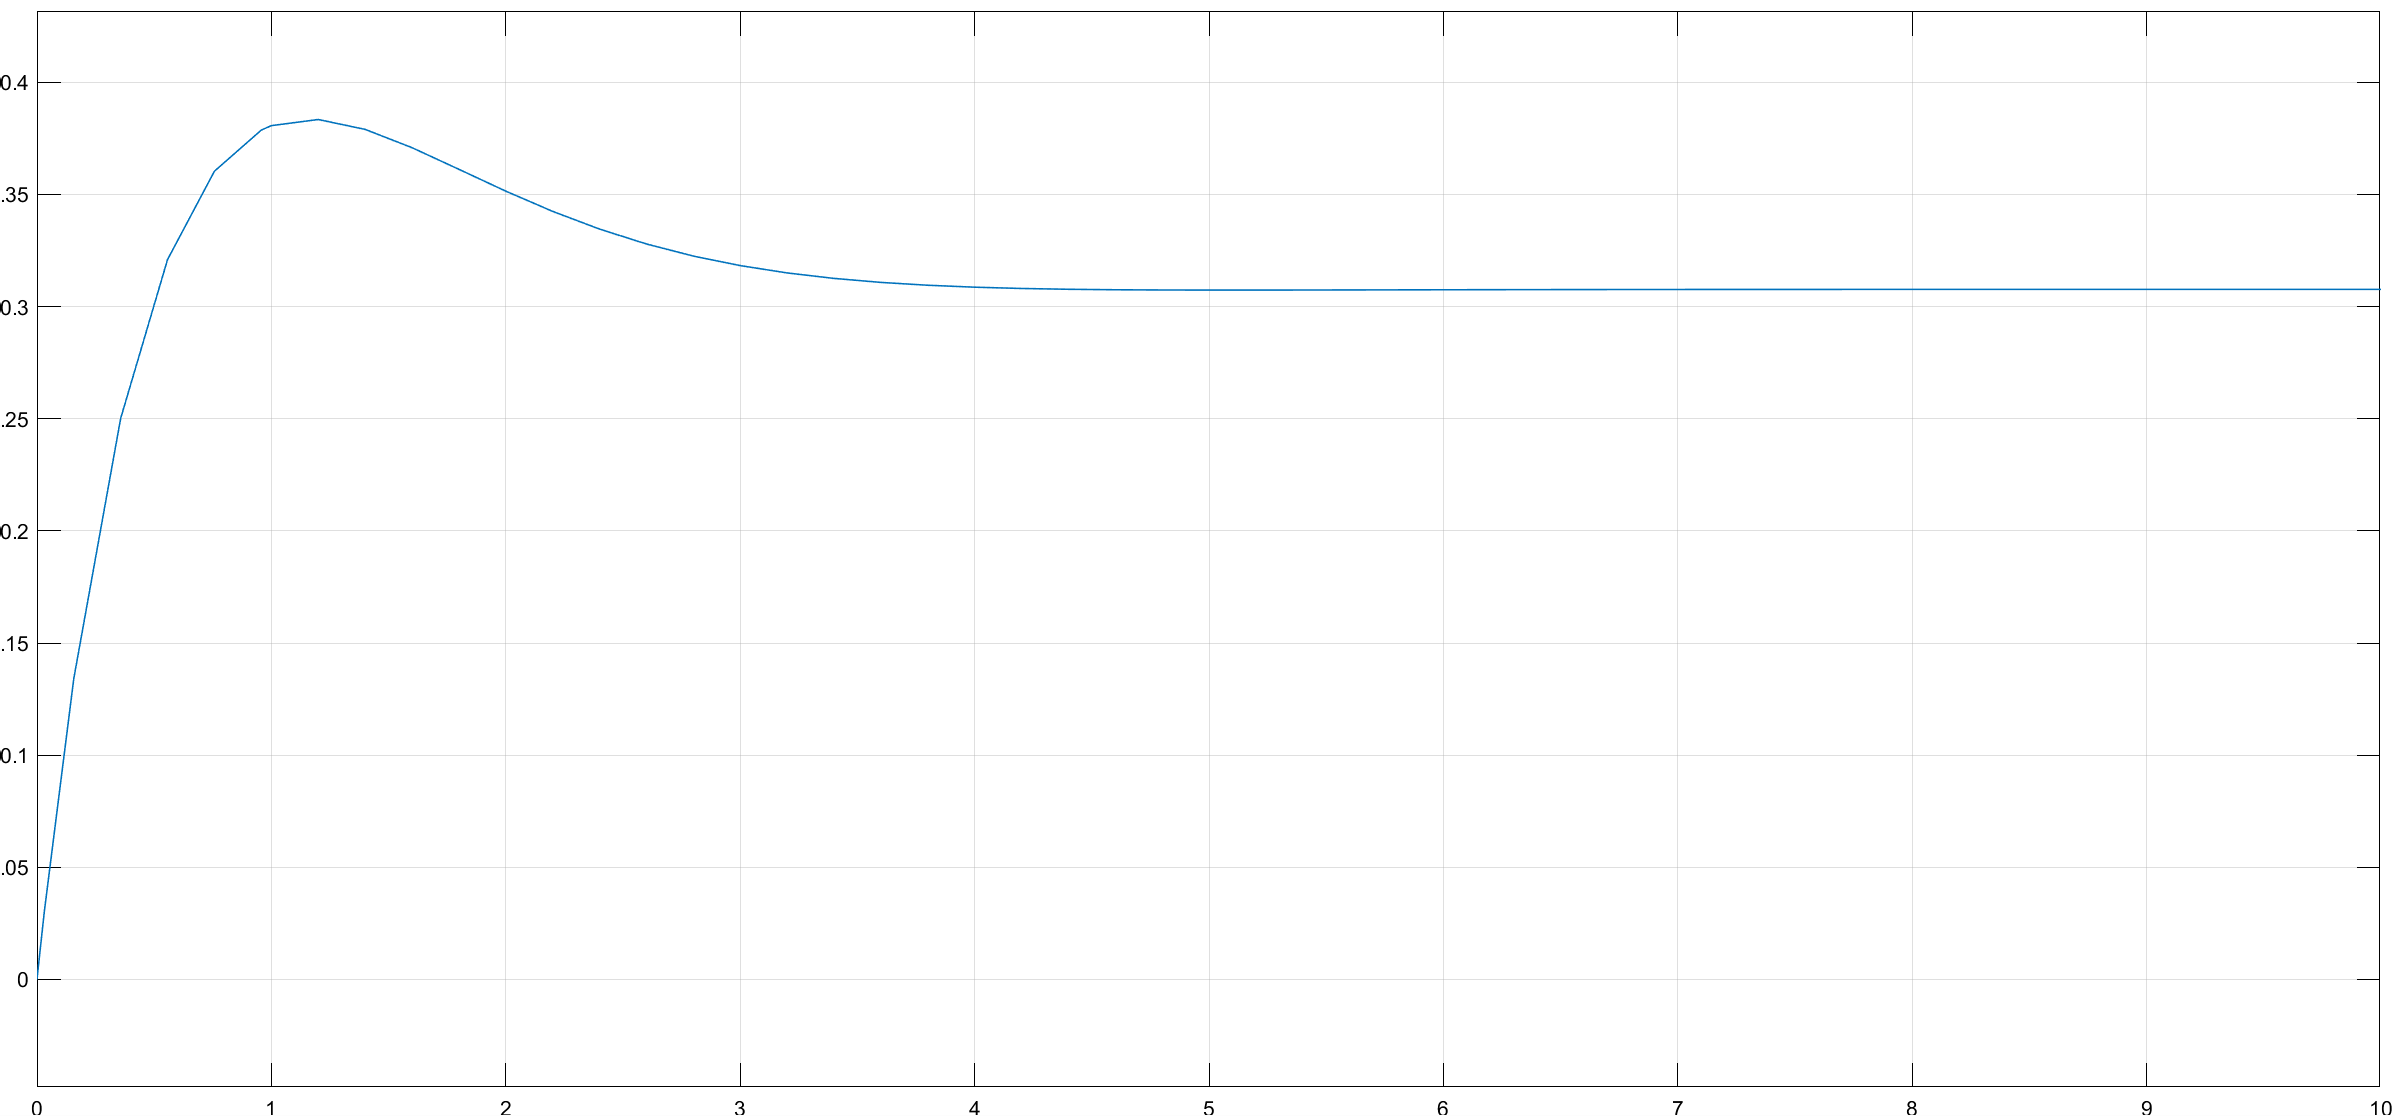

**Insuline**

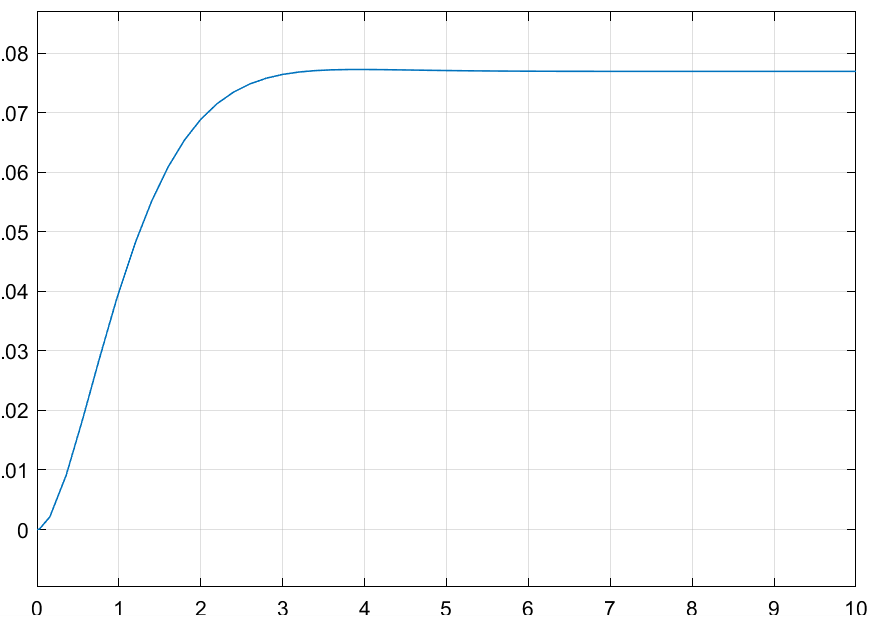

#### Model 2

 $$$ \frac{\mathrm{d}i}{\mathrm{d}t}$ = −0.63𝑖+0.13𝑔−−−−−−−(1) 

$$$ \frac{\mathrm{d}g
}{\mathrm{d}t}$ = −5𝑖 −2.5𝑔 + 𝐴(𝑡)

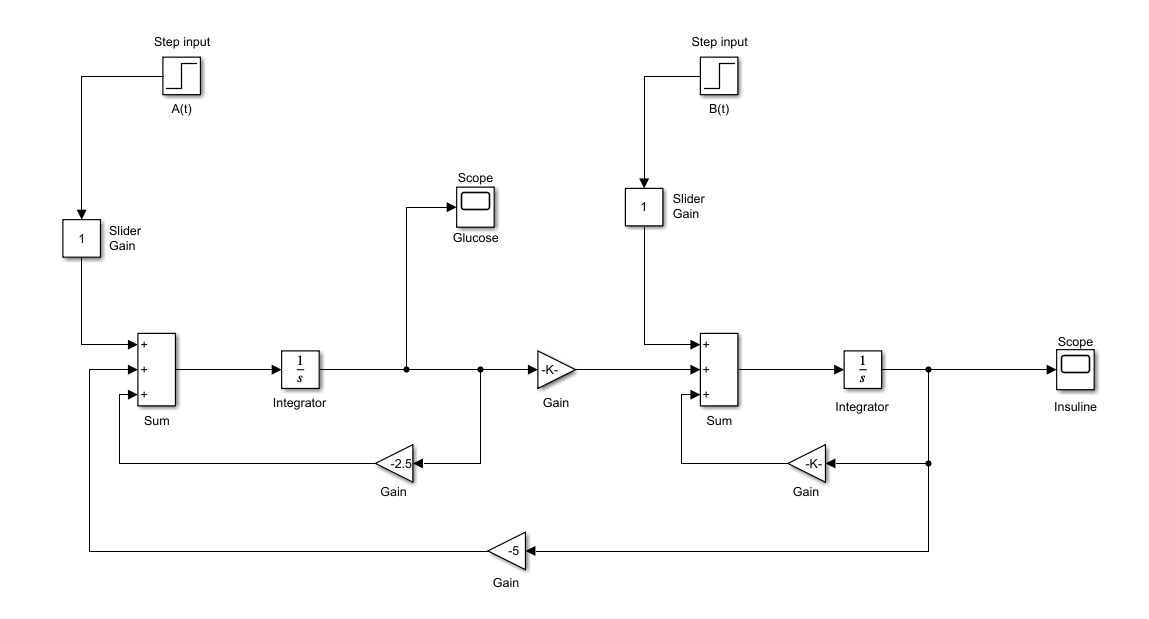

**Glucose**

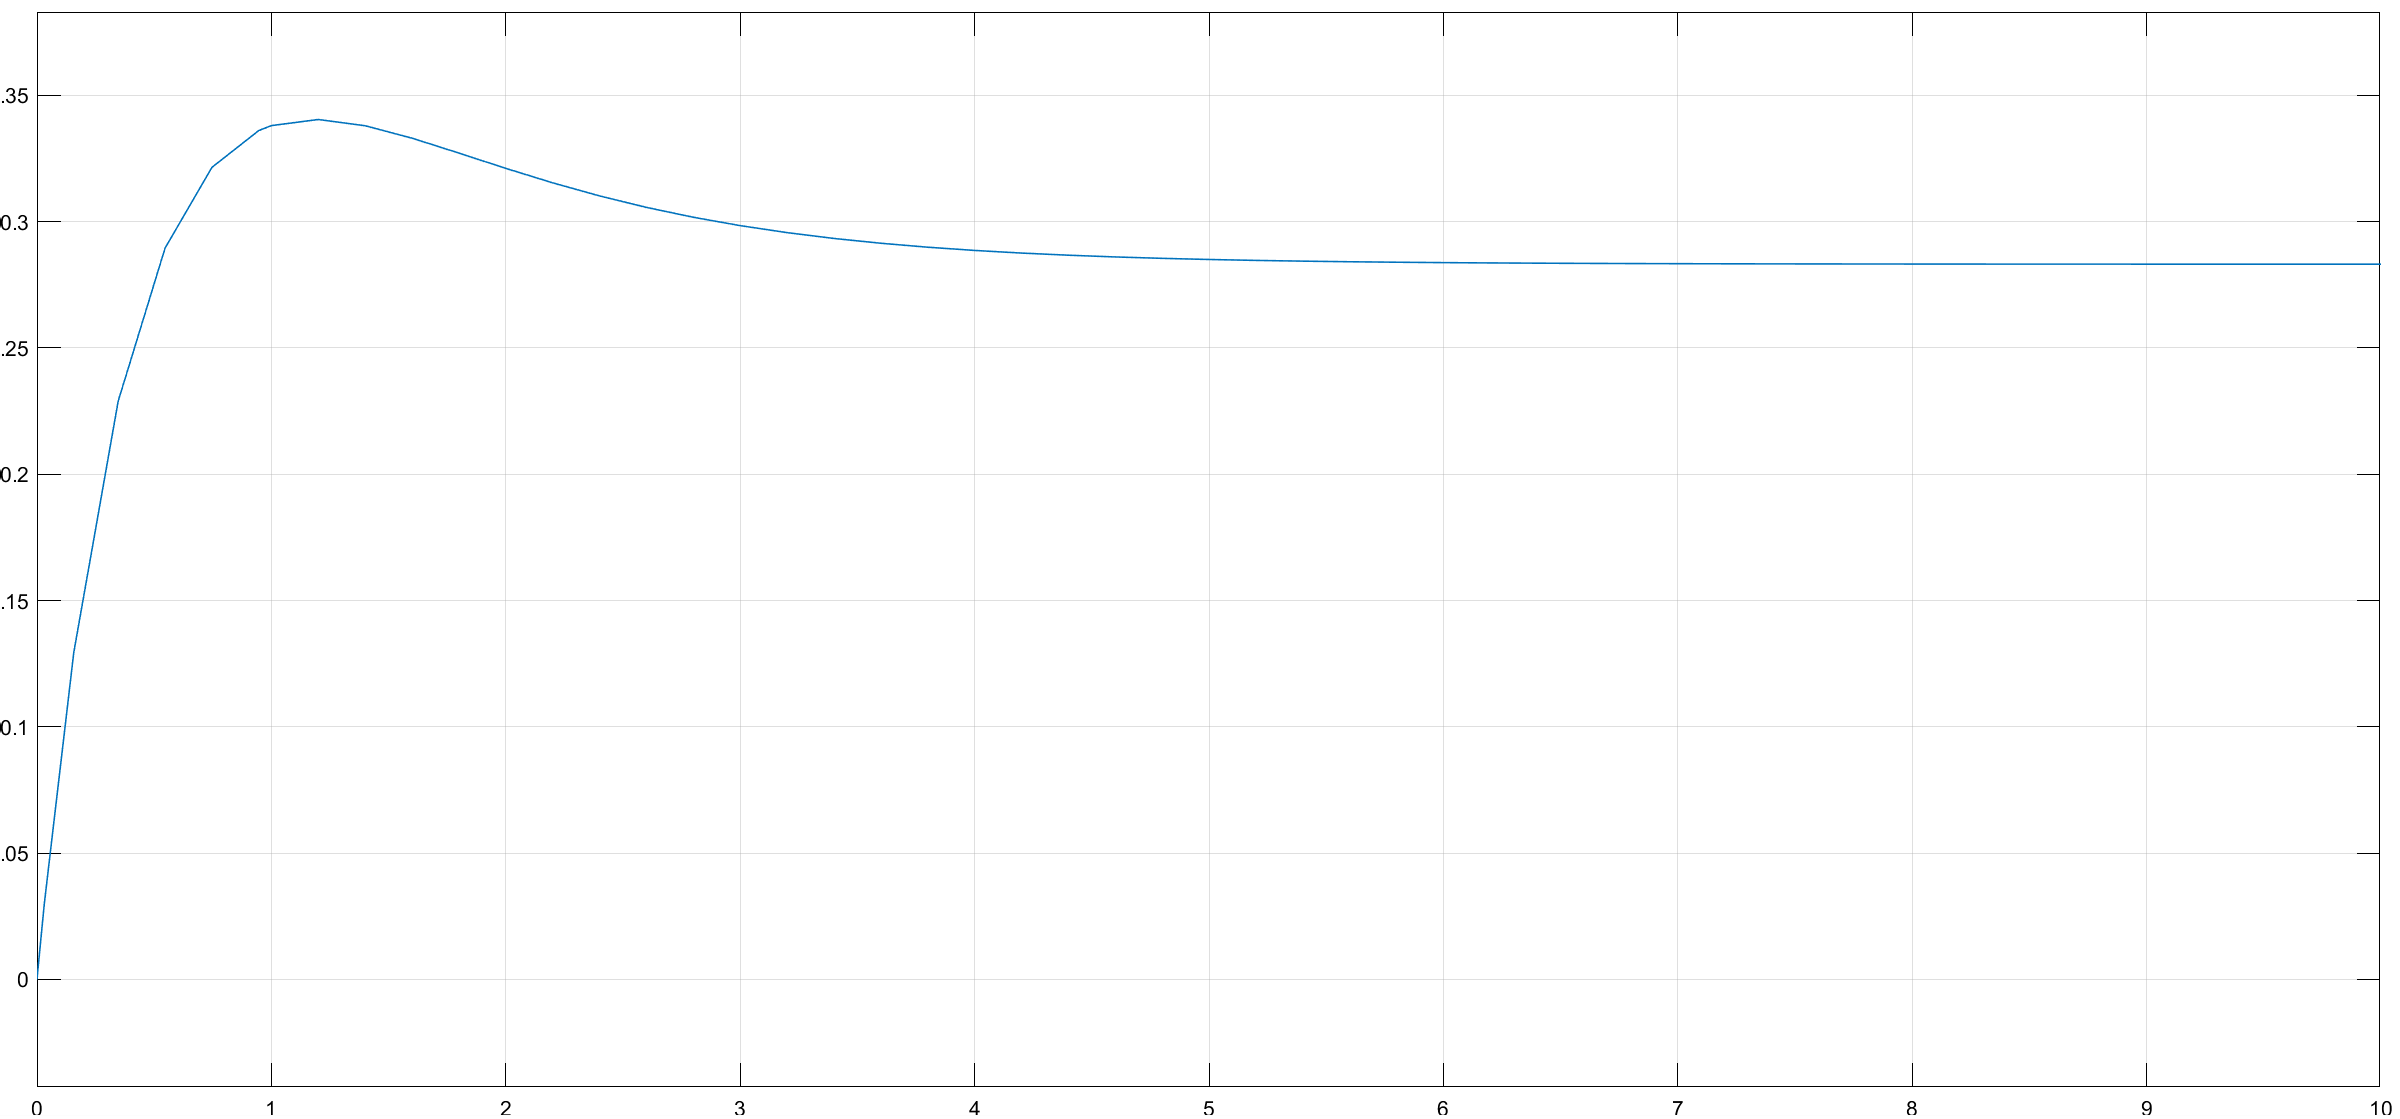

**Insulin**

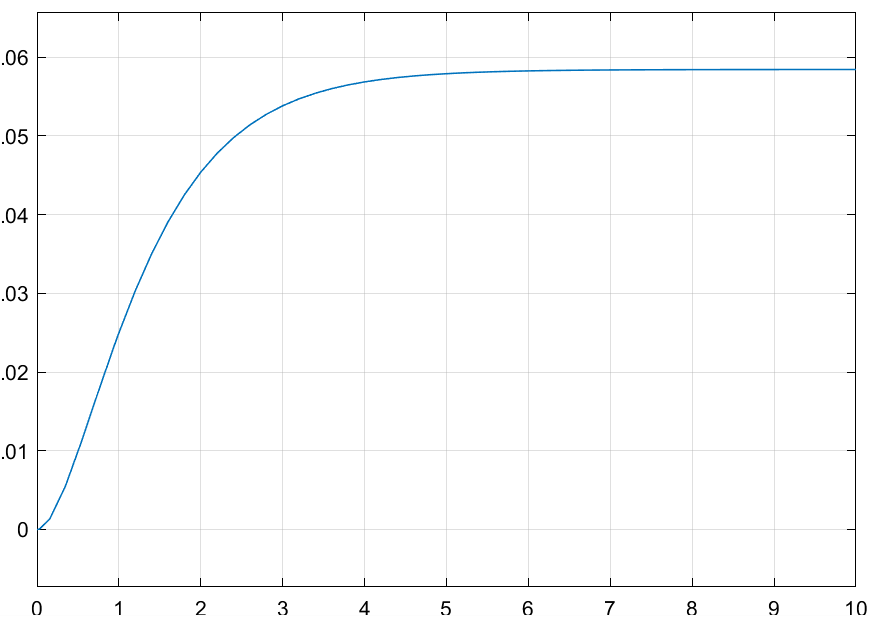

The data shows that the glucose level is higher in the second model, while the insulin level is higher in the first model. This suggests that there is a negative correlation between insulin and glucose levels, meaning that as insulin levels increase, glucose levels decrease. This is because insulin is a hormone that helps to regulate blood sugar levels. When insulin levels are high, it signals cells to take up glucose from the blood, which lowers blood sugar levels.

_

_

### 𝐵(𝑡) = 0.1 U/kg/h in a normal subject

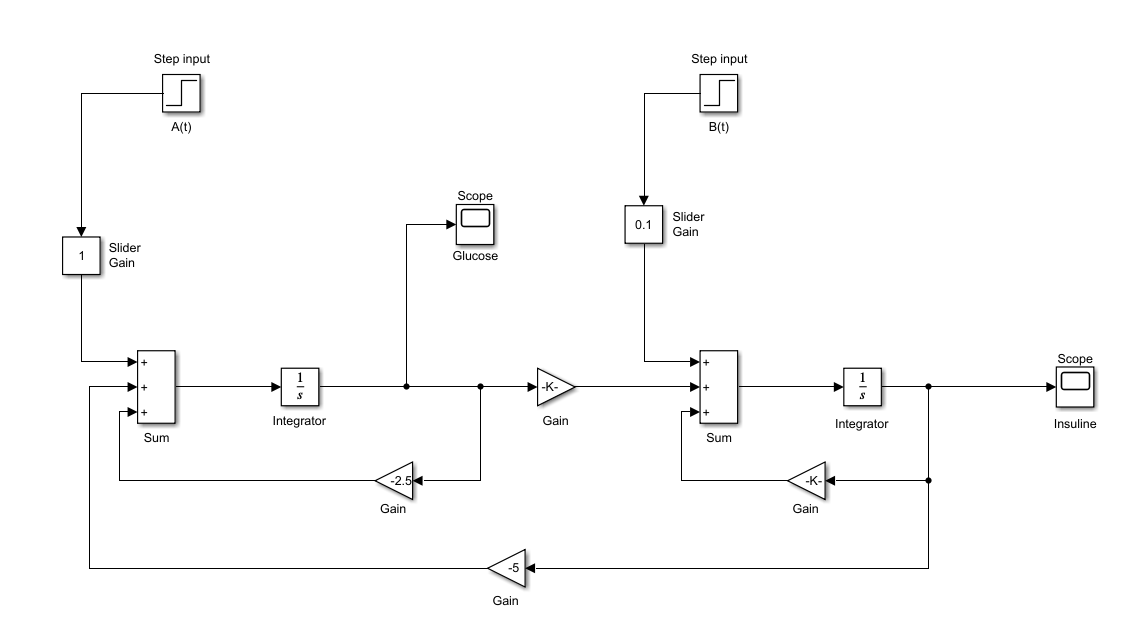

**Glucose**

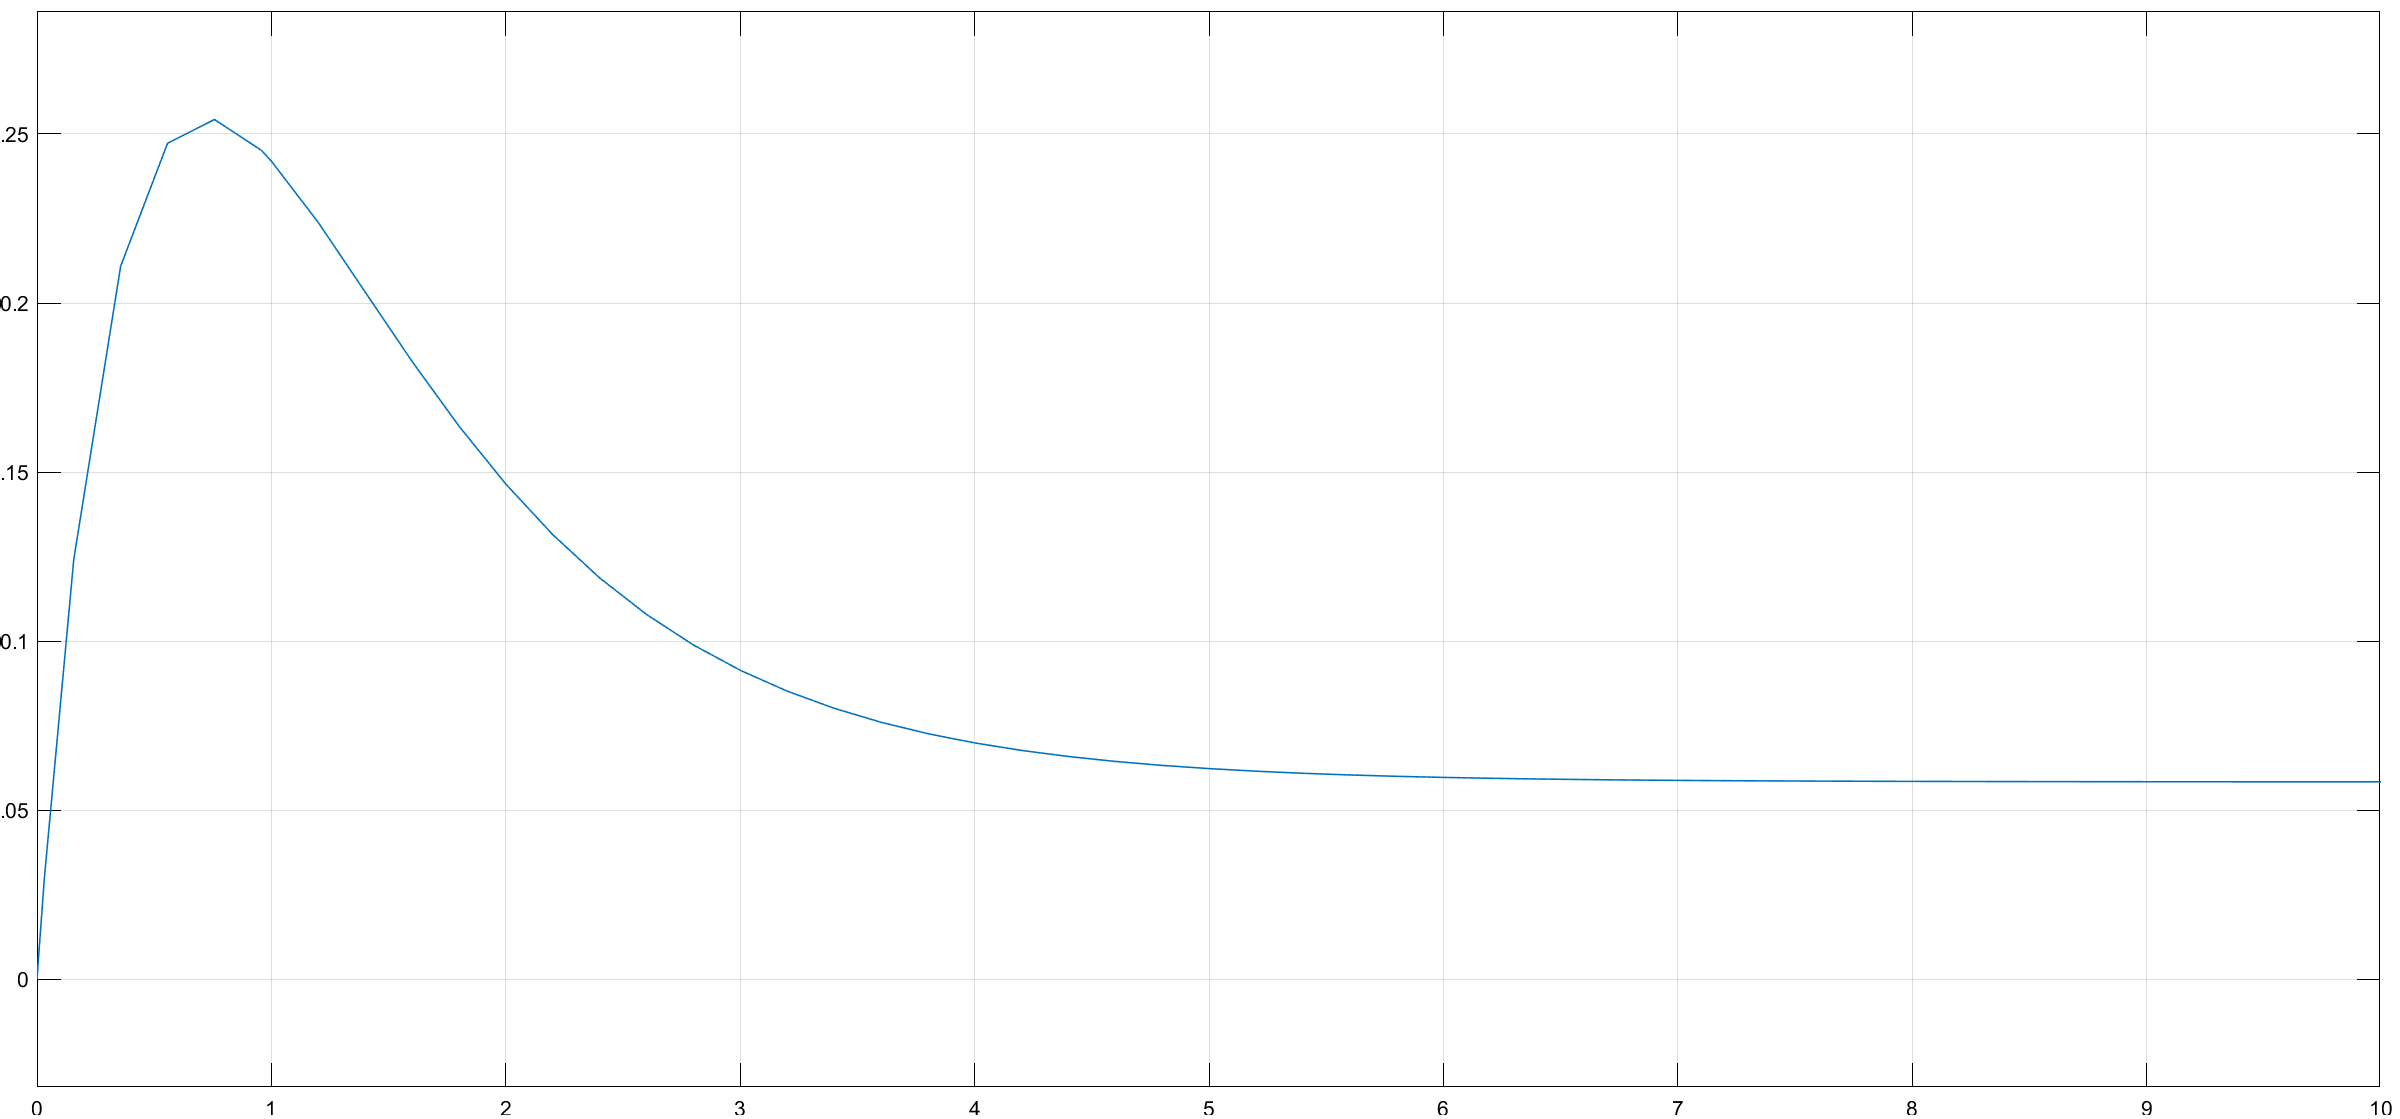

**Insuline**

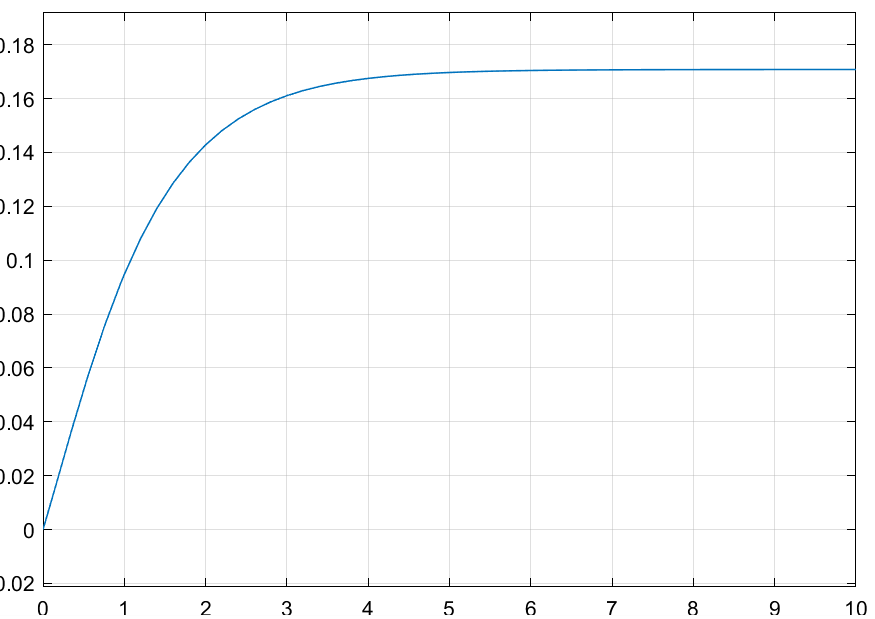

### 𝐵(𝑡) = 0.1 U/kg/h in a diabetic subject

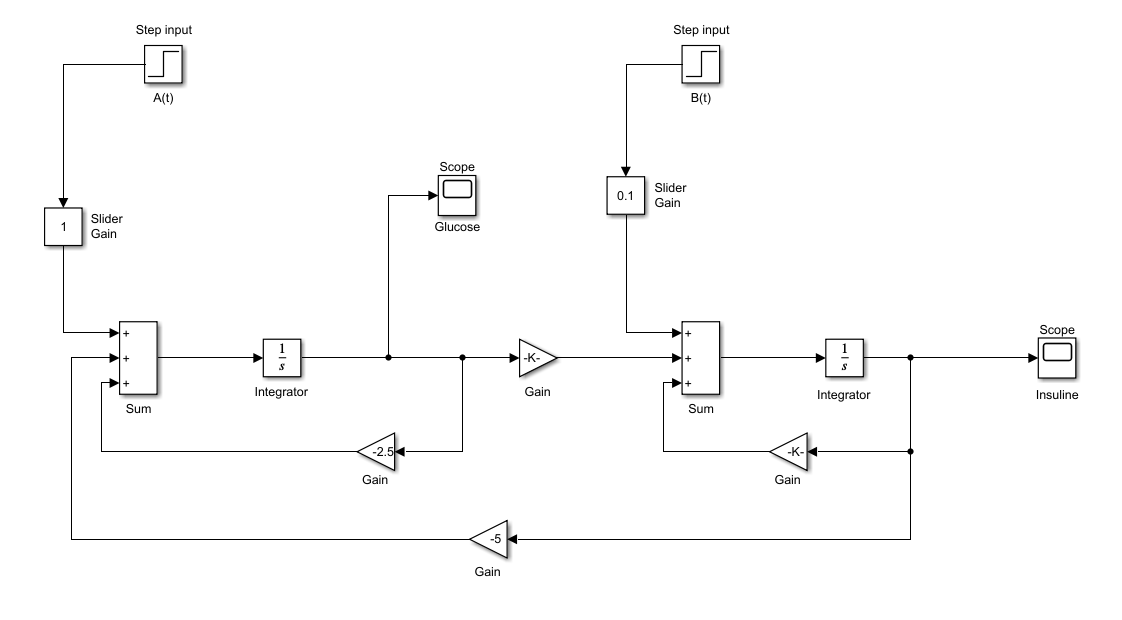

**Glucose**

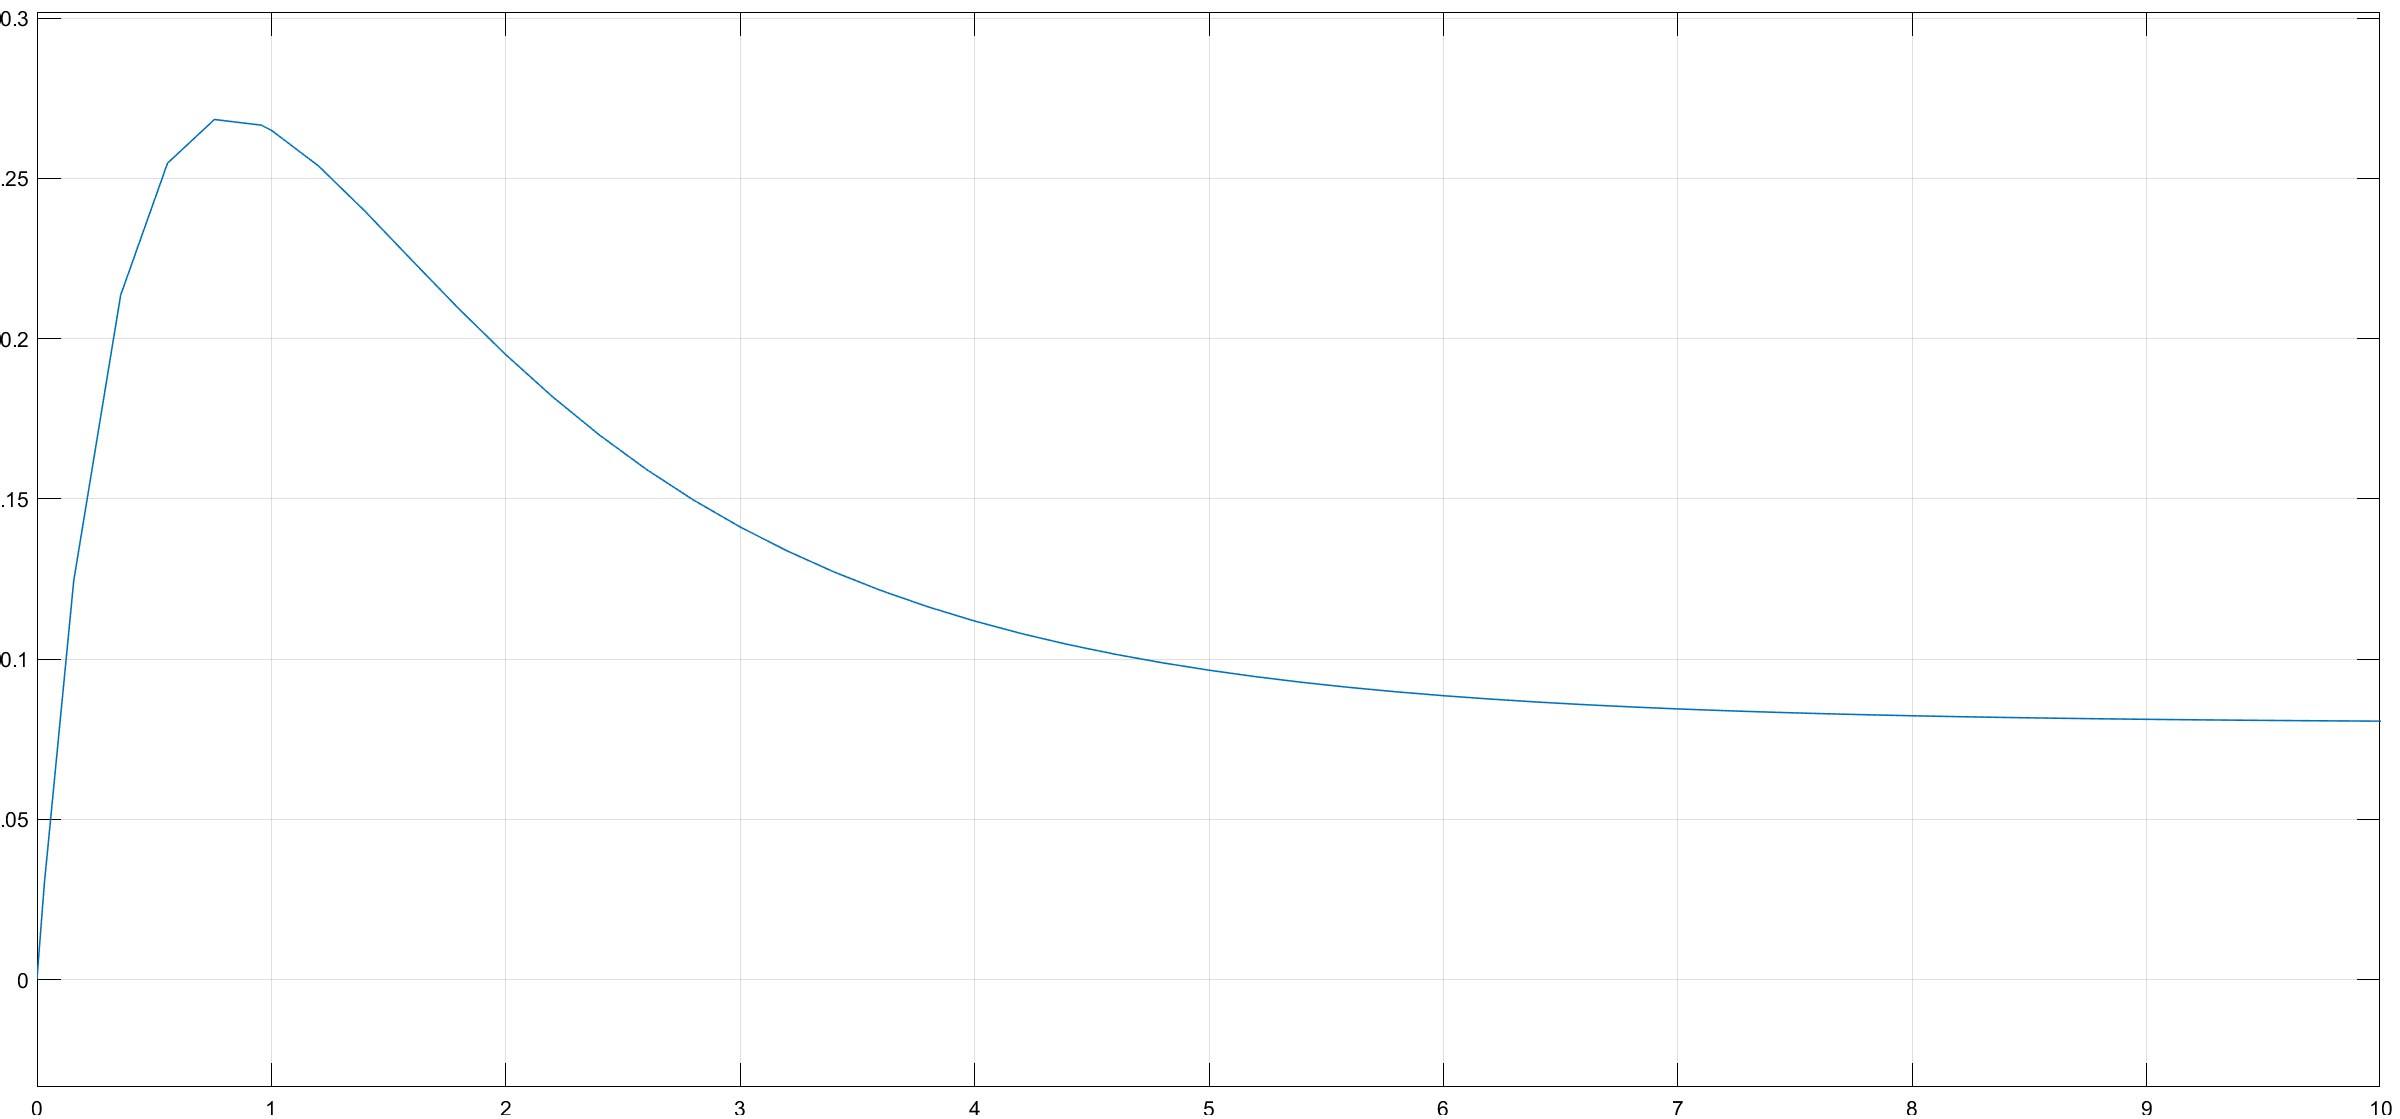

**Insuline**

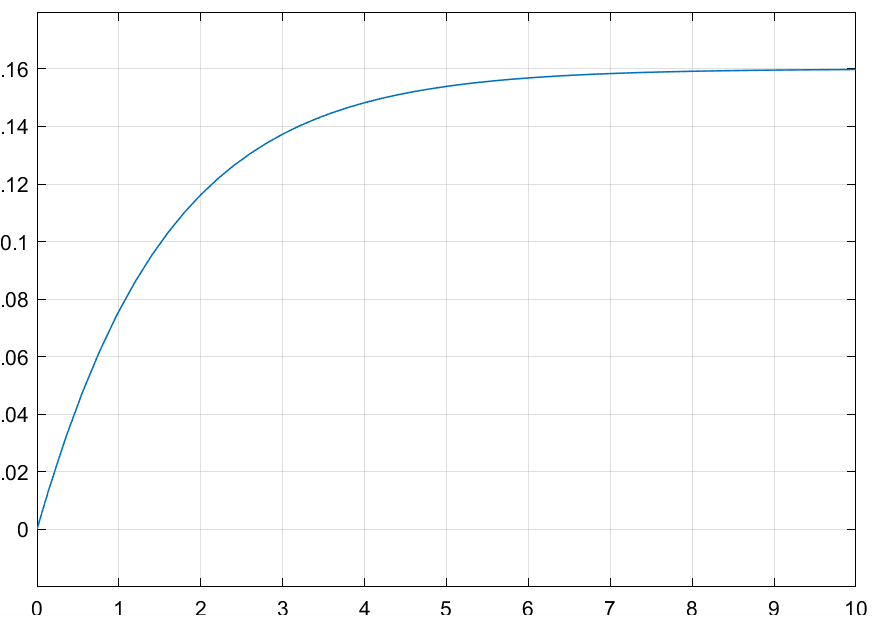

_

_

**1. Riggs iodine model**

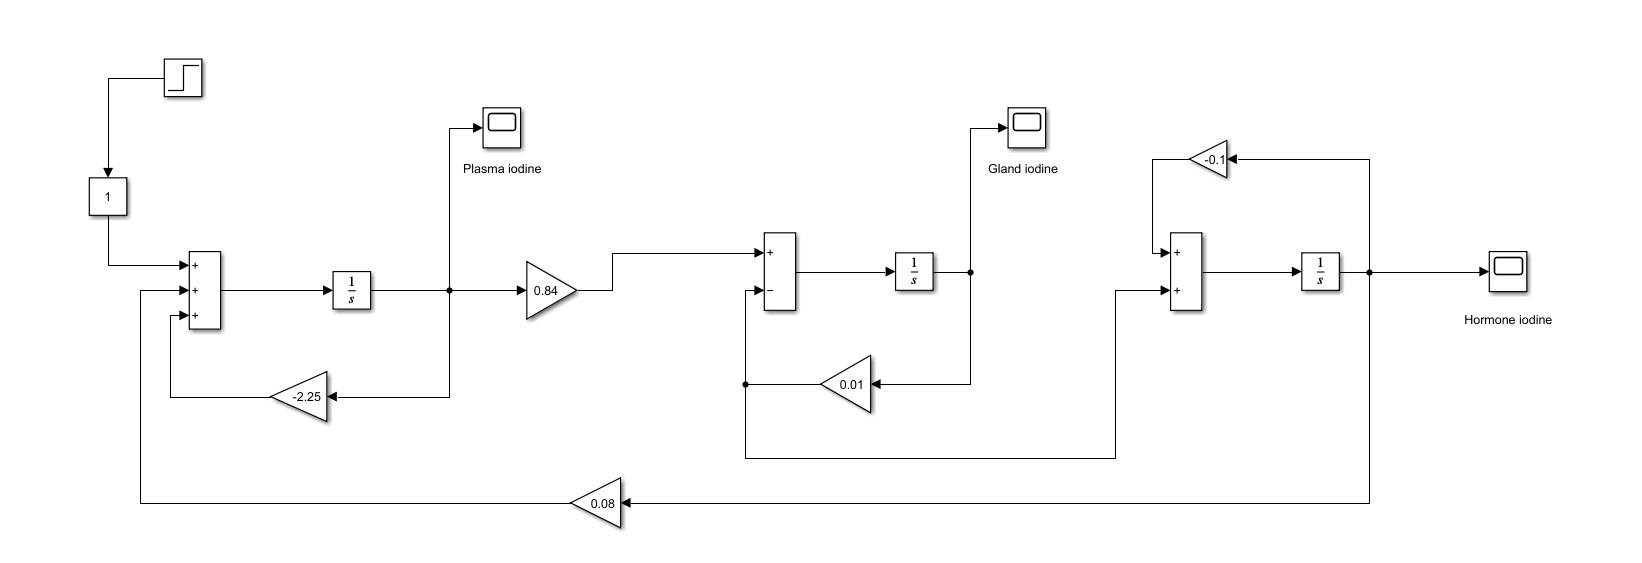

Plasma iodine

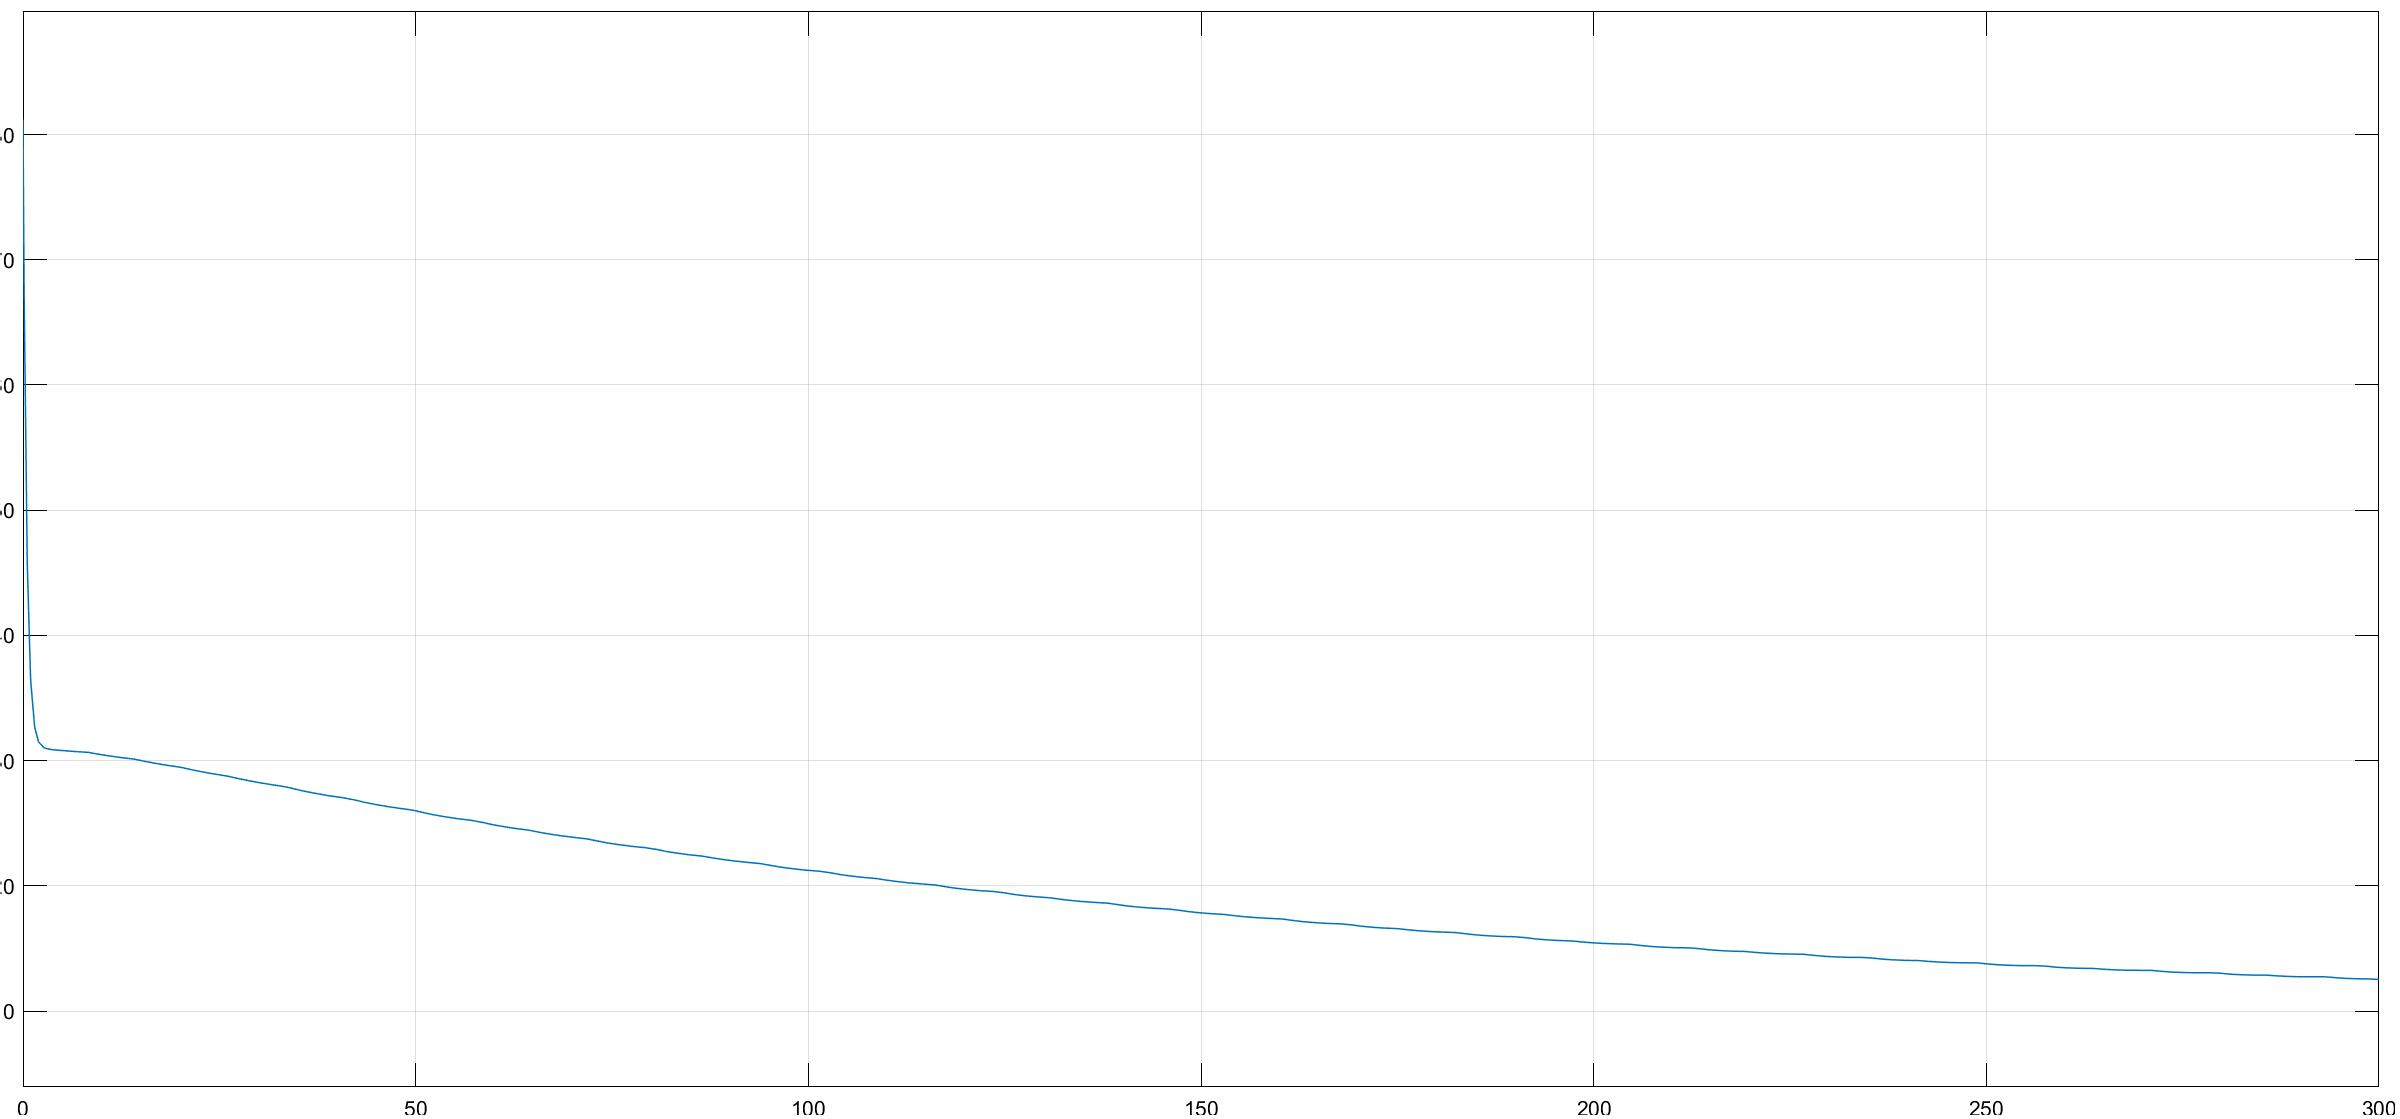

Gland iodine

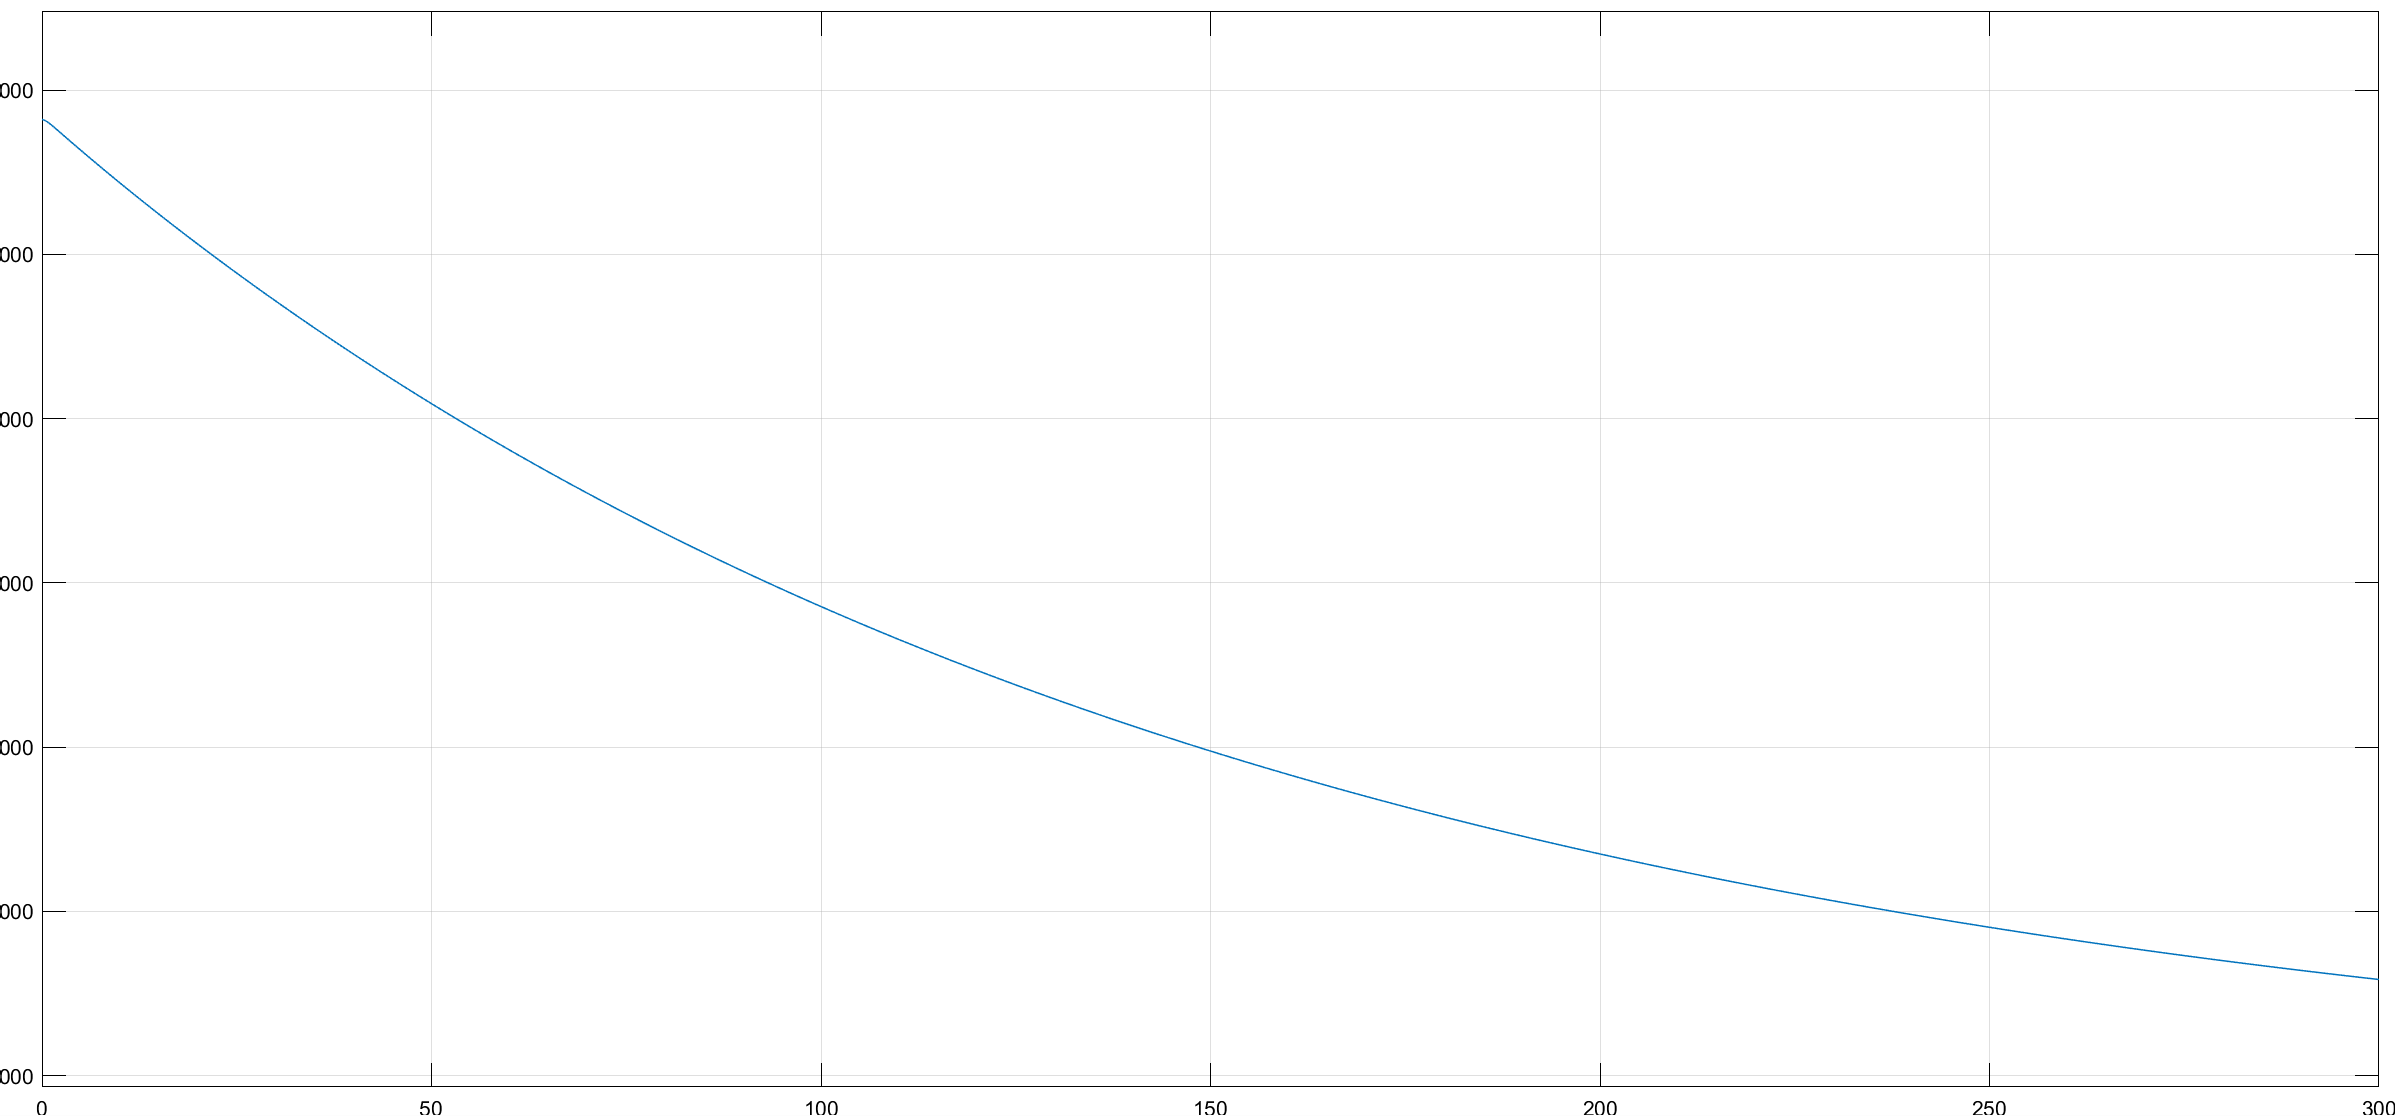

Hormone iodine

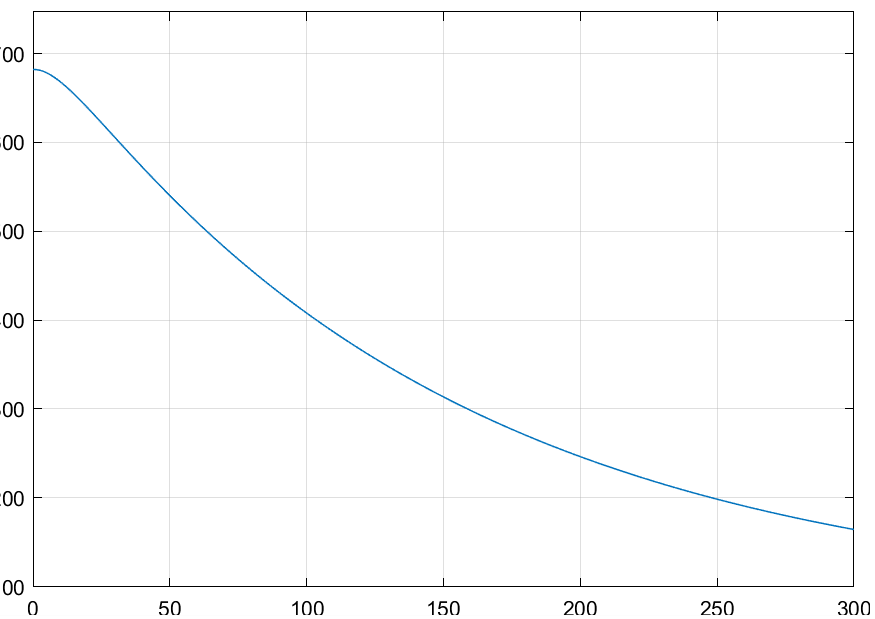

_

_

_

## Part 03

_

### 01

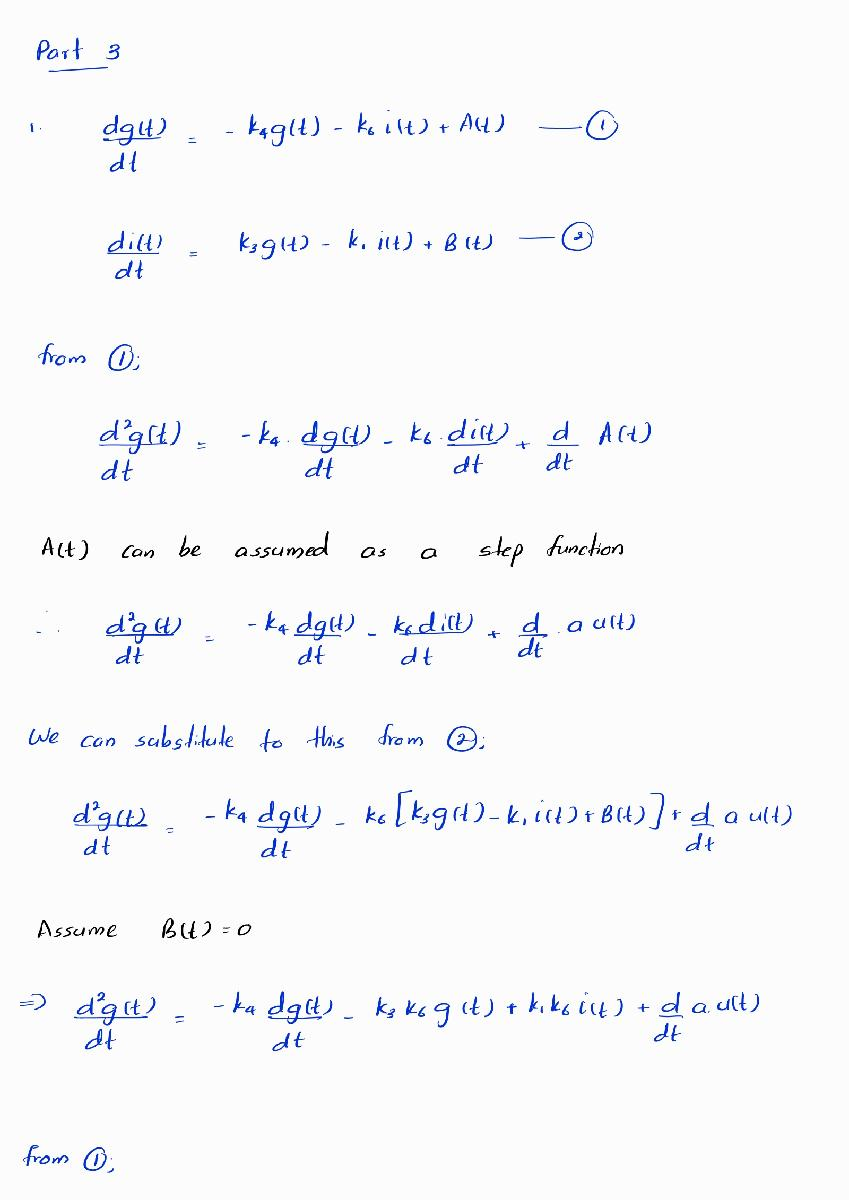

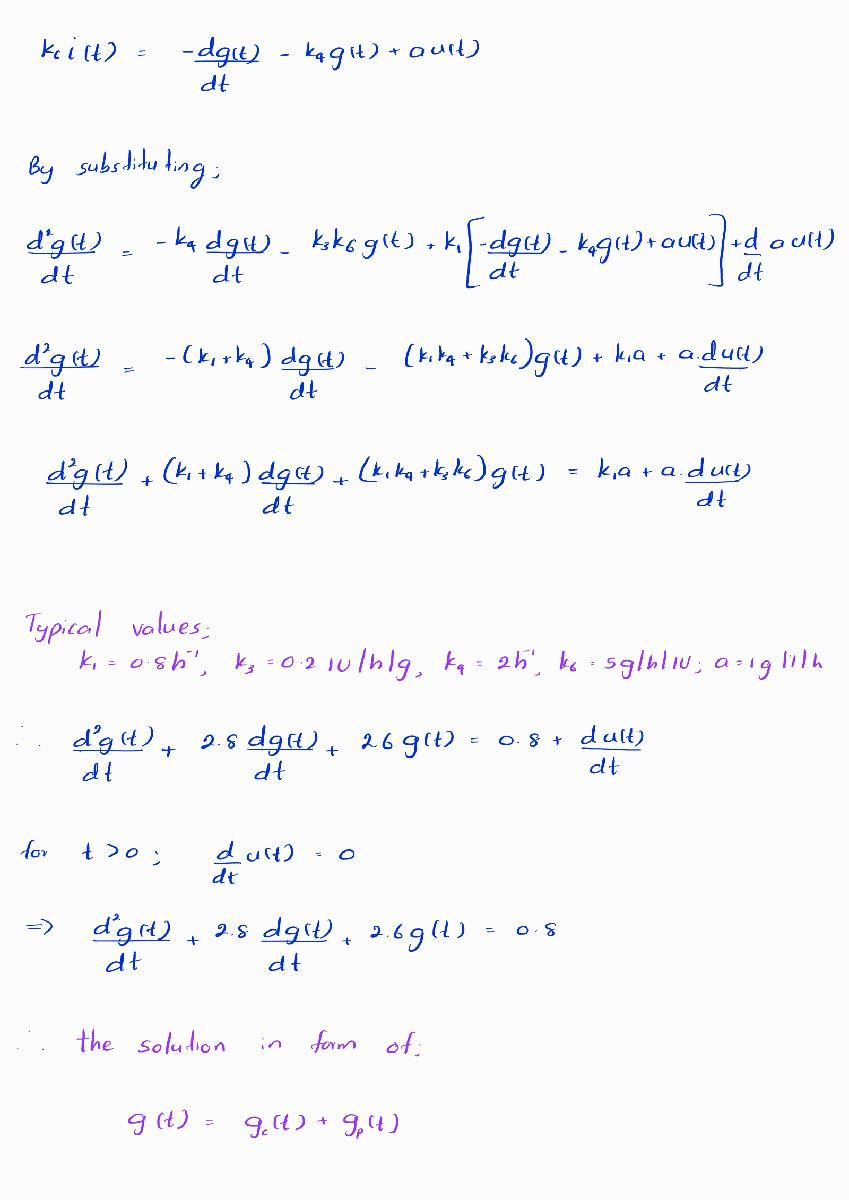

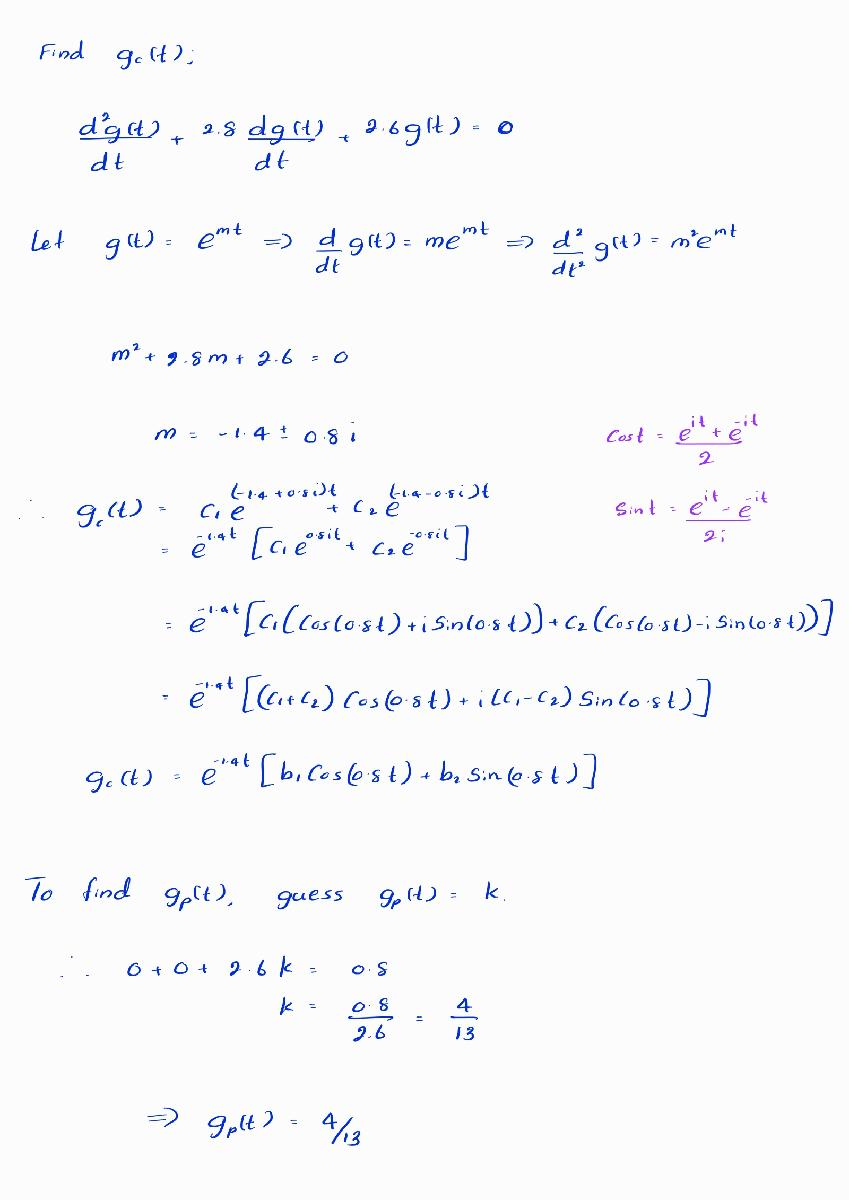

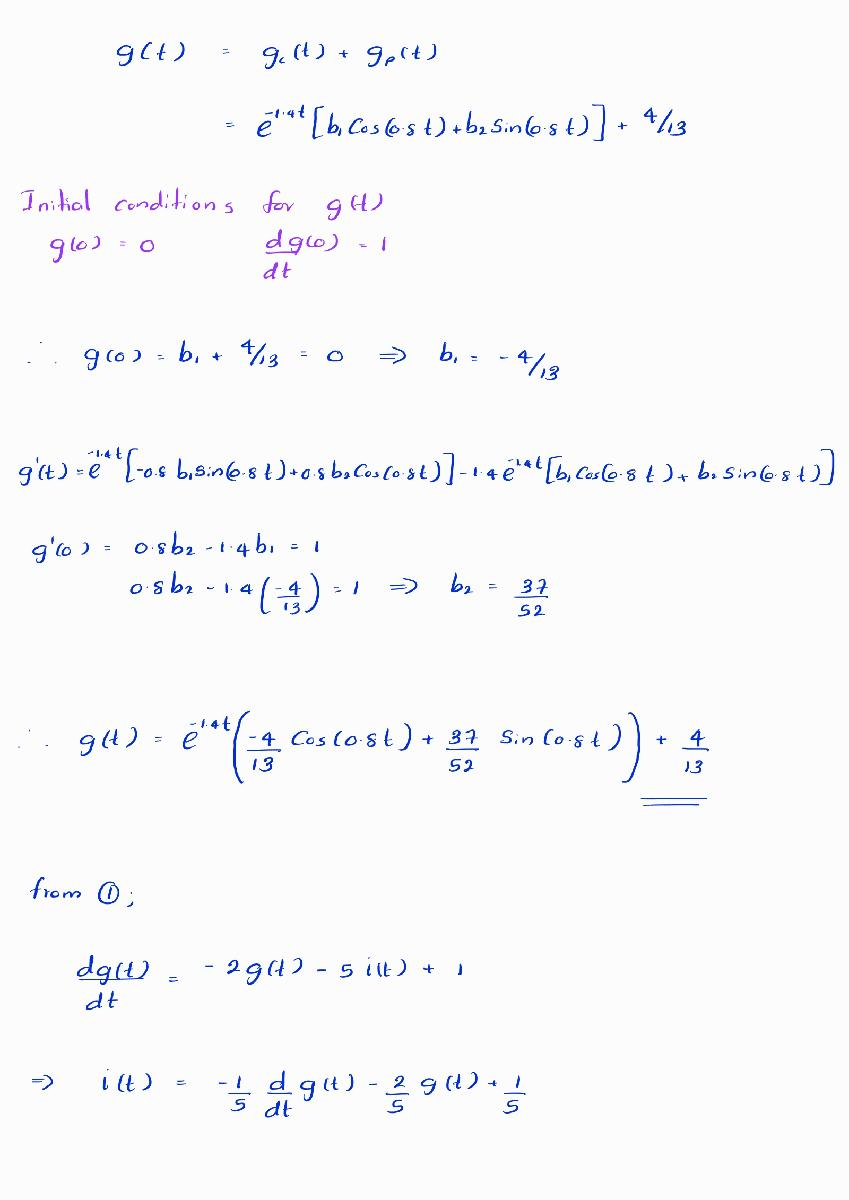

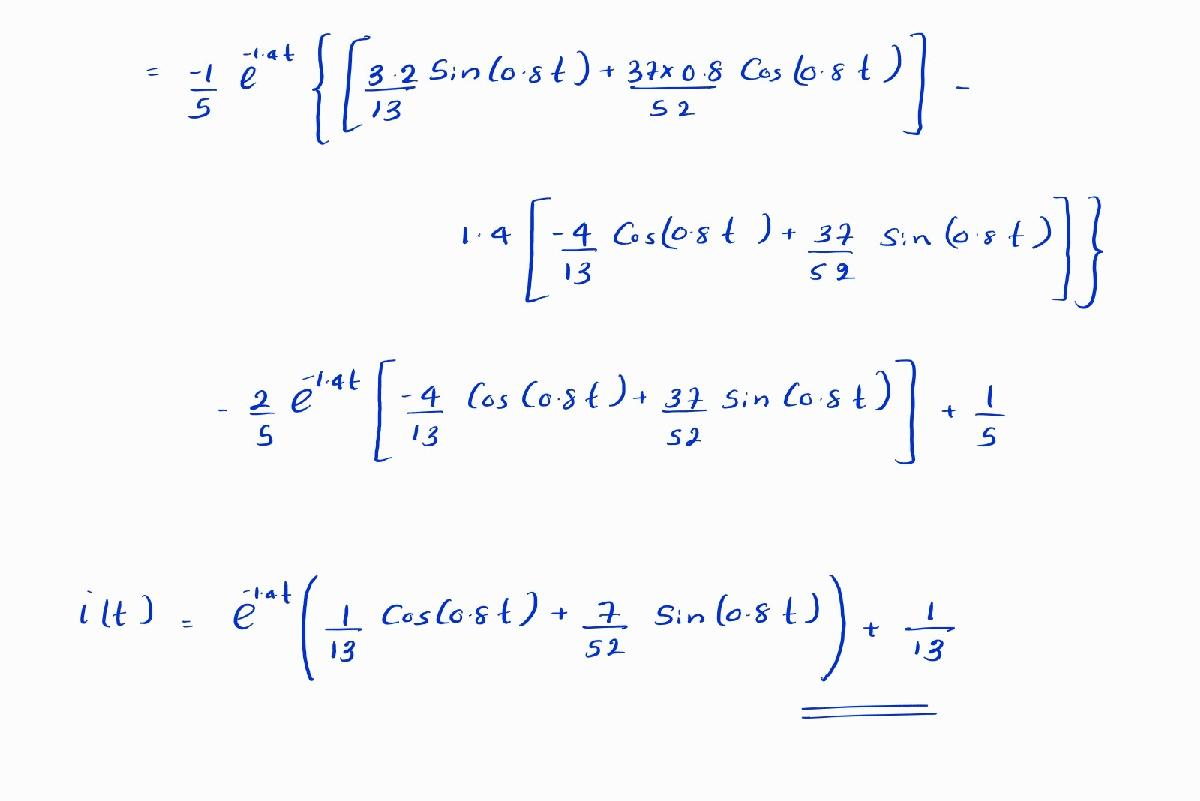

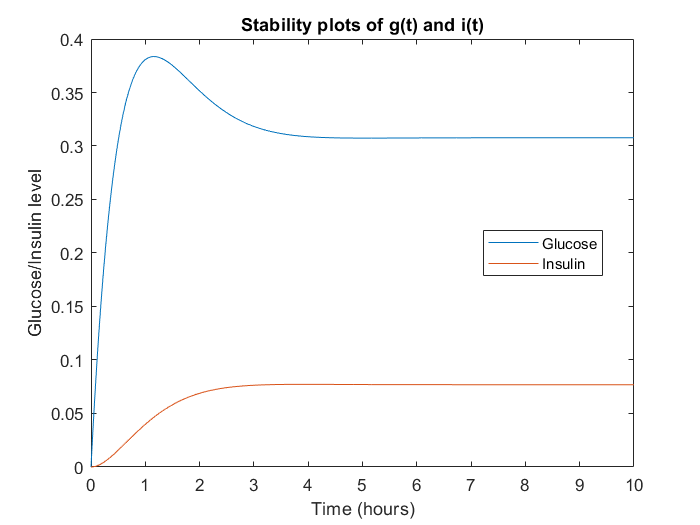

t = 0:0.01:10;
g_t = (exp((-1.4).*t)).*(-(4/13)*cos((0.8).*t) + (37/52)*sin((0.8).*t)) + 4/13; 
i_t = (exp((-1.4).*t)).*(-(1/13)*cos((0.8).*t) - (7/52)*sin((0.8).*t)) + 1/13;
plot(t,g_t,t,i_t);
legend ('Glucose','Insulin',"Location","best")
xlabel ('Time (hours)');
ylabel ('Glucose/Insulin level');
title('Stability plots of g(t) and i(t)');

_

_

### 02

Glucagon is a hormone that is produced by the pancreatic alpha cells. It works in opposition to insulin, which is produced by the pancreatic beta cells. Insulin breaks down glucose into glycogen, which is stored in the liver. Glucagon, on the other hand, converts glycogen back into glucose.

The Bolies model is a simple model that can be used to simulate the effects of insulin on blood glucose levels. The model can be extended to include the effects of glucagon by adding a new compartment to the model: the glucagon compartment. The glucagon compartment would be connected to the liver compartment, and the rate of transfer of glucagon between these compartments would be determined by the glucagon secretion rate and the glucagon degradation rate.

                                   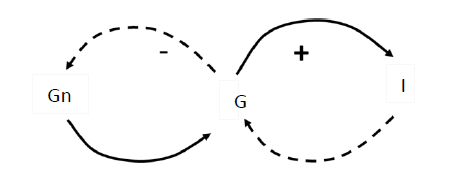

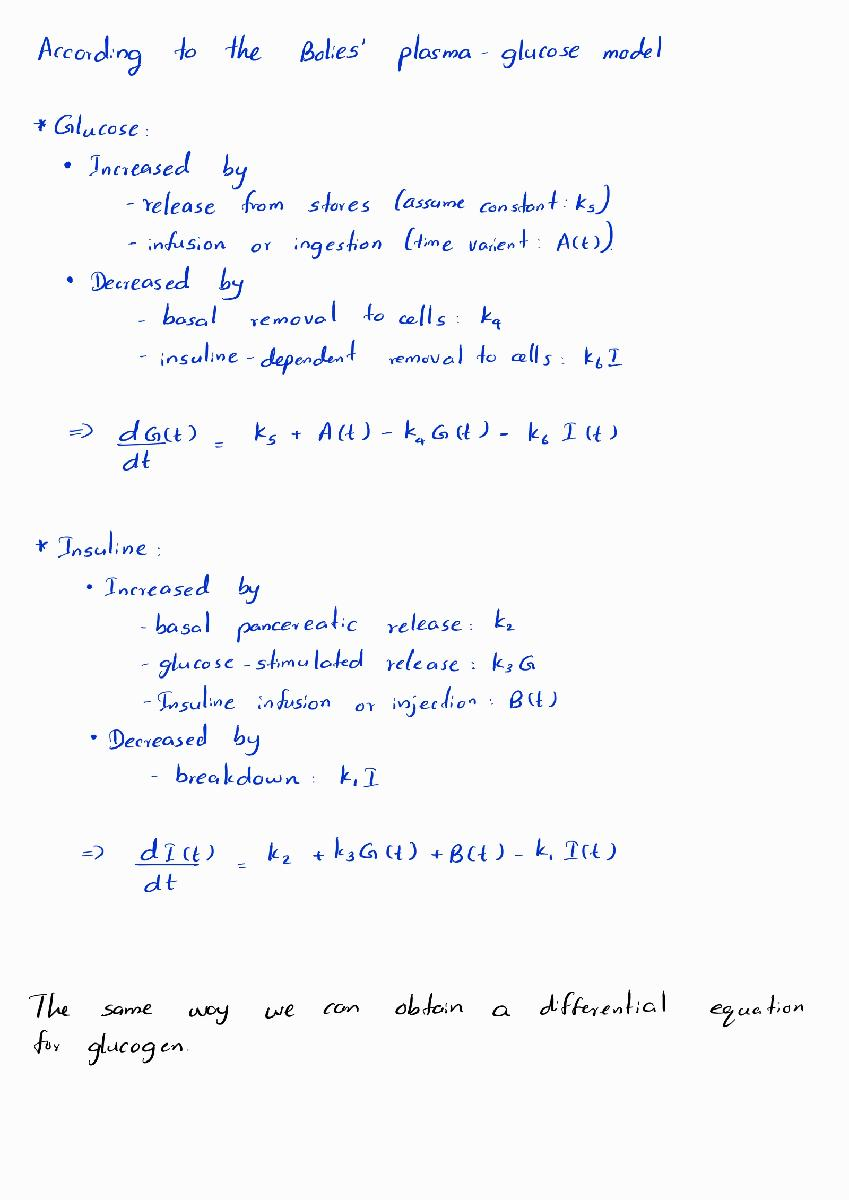

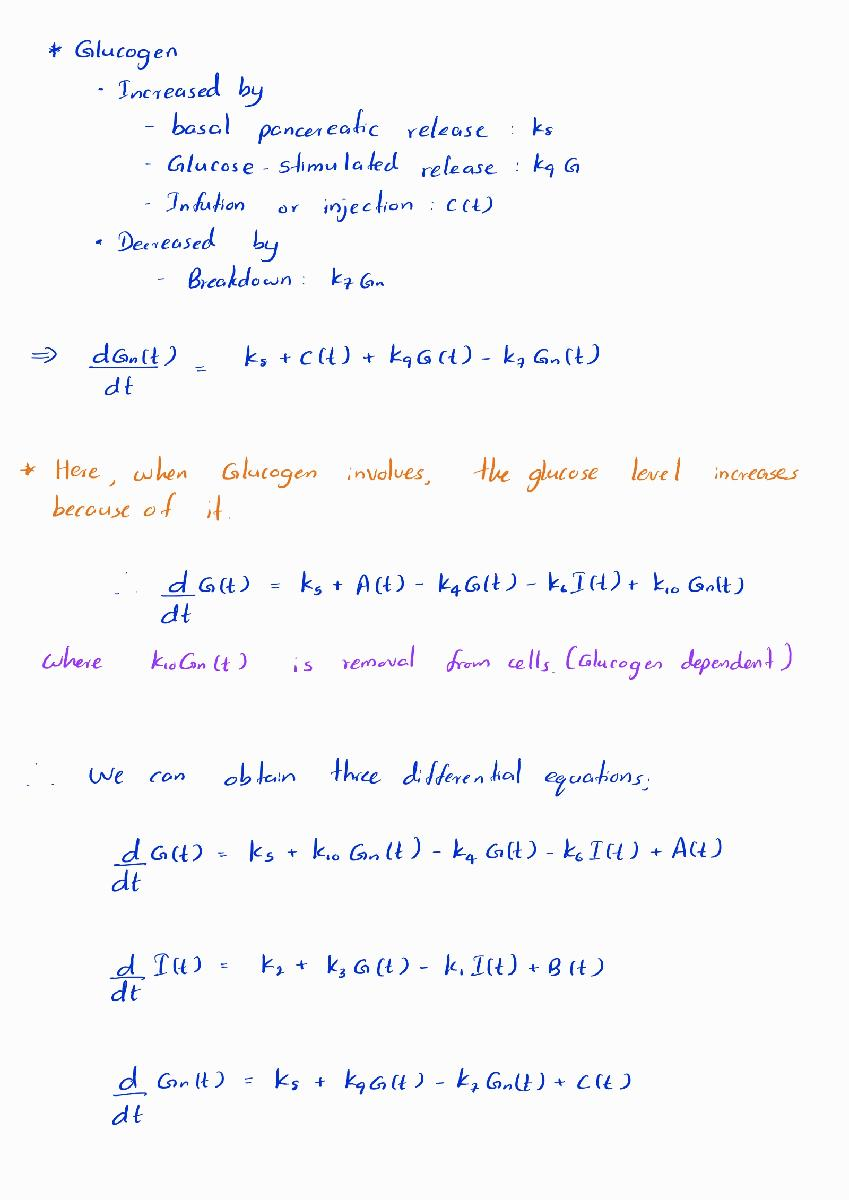

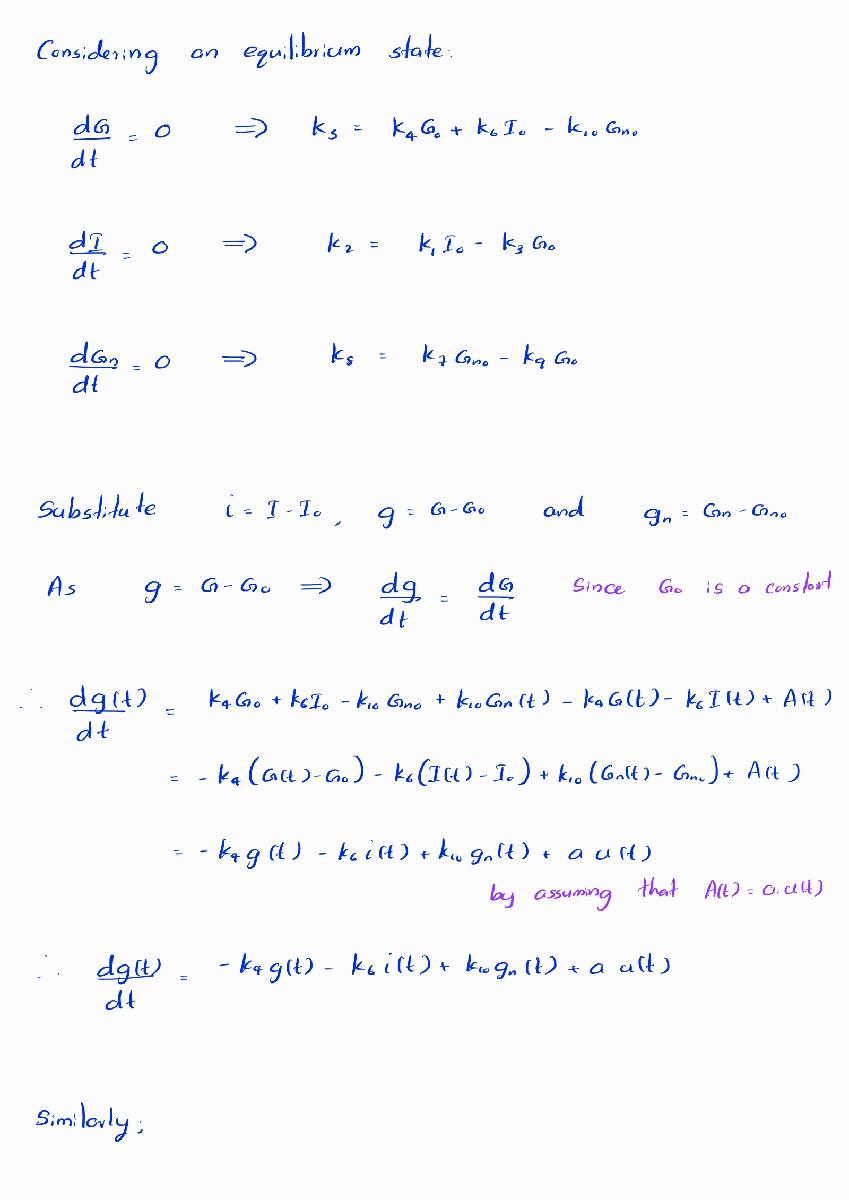

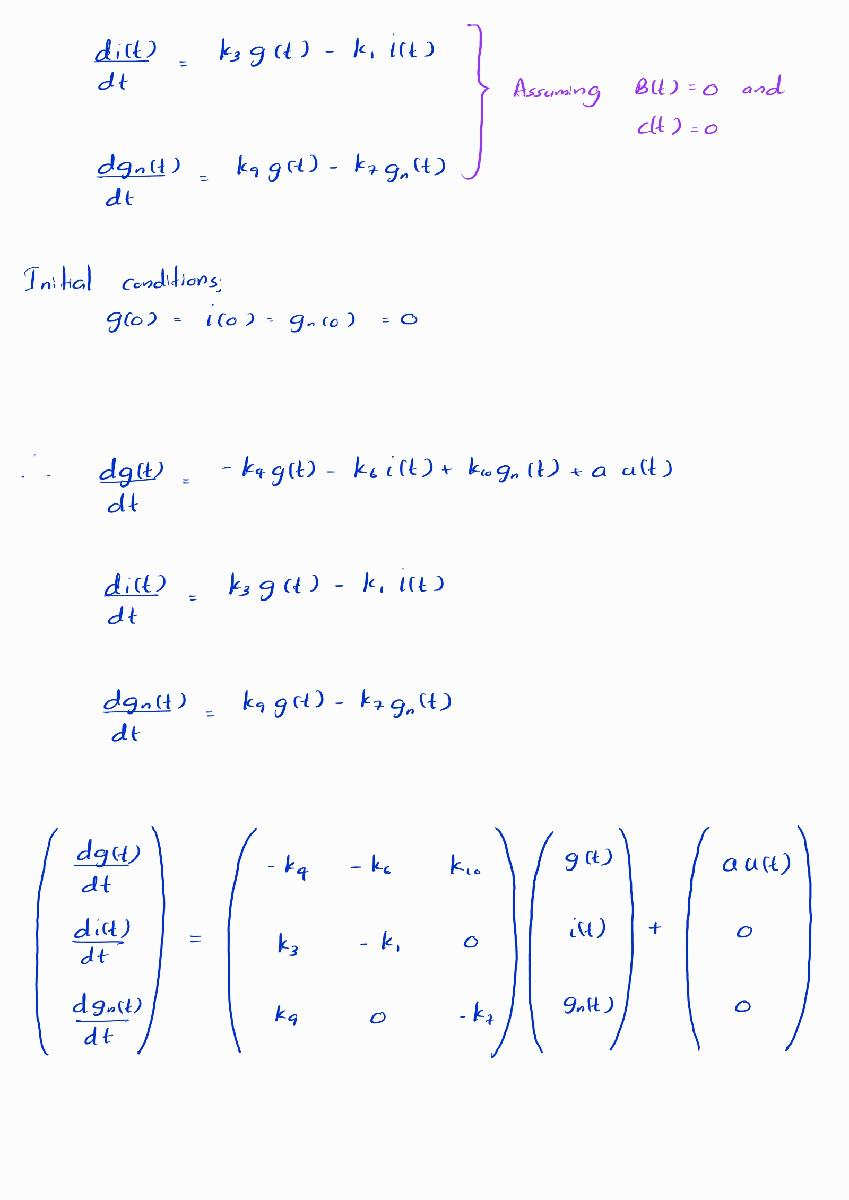

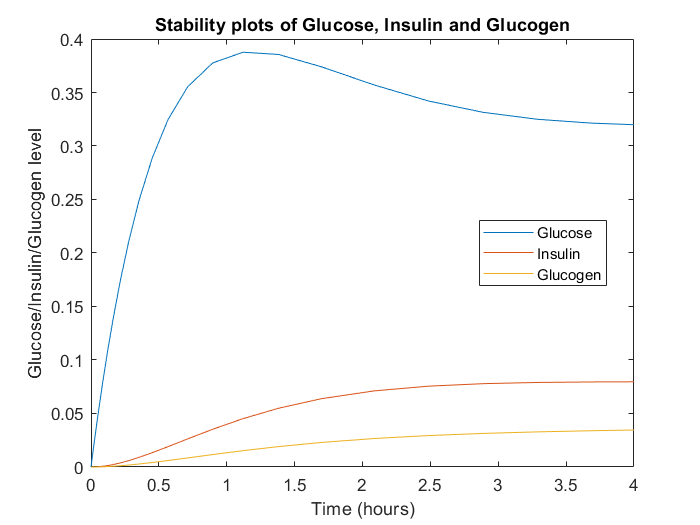

[t,y] = ode23('G_I_Gn_model',[0 4],[0 0 0]);
plot(t,y)
legend ('Glucose','Insulin','Glucogen',"Location","best")
xlabel ('Time (hours)');
ylabel ('Glucose/Insulin/Glucogen level');
title ('Stability plots of Glucose, Insulin and Glucogen')

The graph shows that there is a sudden increase in insulin levels when there is a high glucose input. The insulin level reaches its peak slightly later than the time in which the glucose level hits its maximum. This is because it takes time for the pancreatic cells to detect the increase in glucose levels and to secrete insulin in response.

When glucagon is present, the glucose level is higher at the end point than when glucagon is absent. This is because glucagon opposes the effects of insulin. Insulin lowers blood sugar levels by increasing the uptake of glucose by cells and by stimulating the liver to store glucose as glycogen. Glucagon, on the other hand, raises blood sugar levels by stimulating the liver to break down glycogen into glucose.

When glucagon is present, the pancreas responds to the decrease in glucose levels by secreting more insulin. This helps to keep blood sugar levels from dropping too low. However, the presence of glucagon also means that the glucose level will be higher at the end point than when glucagon is absent.